# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

## Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5.m` - MATLAB script that steps you through the exercise. (Not needed if using `ex5.mlx.)`

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

## Setting up your environment

Run the commands below to clear your workspace of existing variables, display your current directory, and list the files in your current directory. You should see all of the files above listed. If they are not, change you Current Folder to the **ex5** exercise folder.

To run the code inside of a MATLAB Live Script section:

- Click into the section to make it active. A blue bar will appear on the left.

- Click either the **Run Section (CTRL+ENTER)** or **Run and Advance (CTRL+SHIFT+ENTER) **buttons in the **Live Editor** tab above. Alternatively, you can click on the blue bar.

The **Run All** and **Run to End** are not recommended for use in these exercises. Executing the Live Script from the command line is also not recommended. 

% Clear existing variables
clear;
% Remove existing exercises from search path, list current working directory, and list files in current directory
cleanPath();

ans = 'D:\Machine Learning\week6\machine-learning-ex5\ex5'


.                        ex5data1.mat             lib                      submit.m                 
..                       featureNormalize.m       linearRegCostFunction.m  token.mat                
ex5.m                    fmincg.m                 plotFit.m                trainLinearReg.m         
ex5.mlx                  learningCurve.m          polyFeatures.m           validationCurve.m        



# 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

## 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

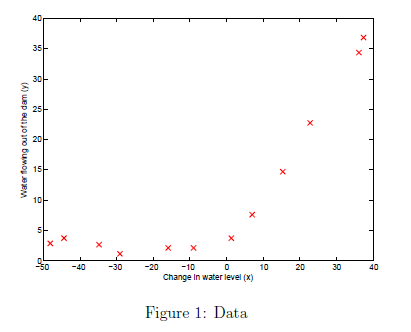

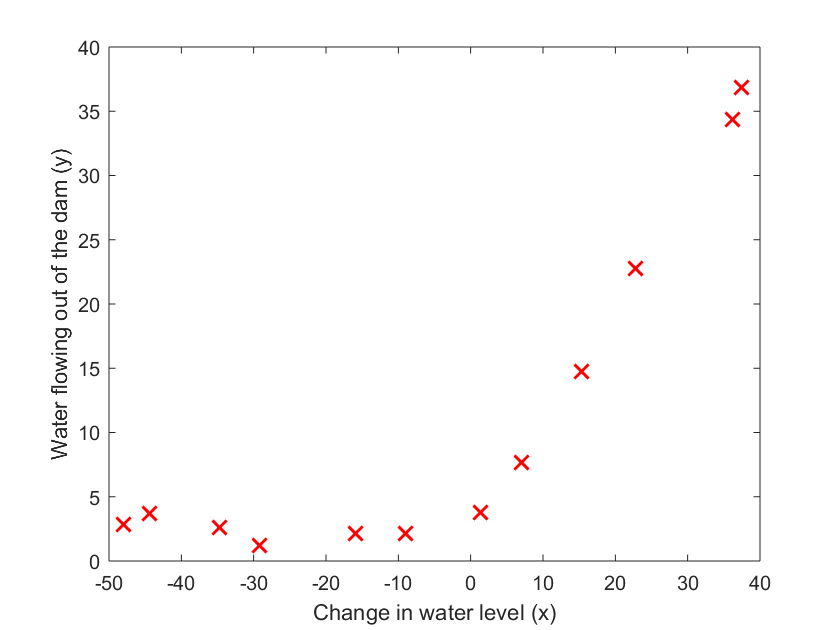

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

## 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^{m} {\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\text{ }\lambda }{2m}\left(\sum_{j=1}^{n} \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overtting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\text{ }1}{m}\sum_{i=1}^{m} \text{ }\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \text{ }\text{ }\mathrm{for}\text{ }\text{ }j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\text{ }1}{m}\sum_{i=1}^{m} \text{ }\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \text{  }\text{ }\mathrm{for}\text{ }\text{ }j=0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

Undefined function or variable 'theta'.

fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

grad =   -11.2176
 -245.6520


grad =   -11.2381
 -242.2045


grad =   -11.2790
 -235.3094


grad =   -11.4018
 -214.6242


grad =   -11.7704
 -152.5687


grad =   -12.6798
    0.5790


Iteration     1 | Cost: 1.052435e+02


grad =   -11.2240
    0.5125


grad =    -8.3124
    0.3796


grad = 	1.0e+-10 *

   -0.0012
    0.5174


Iteration     2 | Cost: 2.237391e+01


grad = 	1.0e+-5 *

    0.0027
   -0.4519


grad = 	1.0e+-6 *

    0.0027
   -0.4518


grad = 	1.0e+-6 *

    0.0018
   -0.3012


grad = 	1.0e+-6 *

    0.0012
   -0.2008


grad = 	1.0e+-6 *

    0.0008
   -0.1338


grad = 	1.0e+-7 *

    0.0053
   -0.8919


grad = 	1.0e+-7 *

    0.0035
   -0.5943


grad = 	1.0e+-7 *

    0.0024
   -0.3960


grad = 	1.0e+-7 *

    0.0016
   -0.2637


grad = 	1.0e+-7 *

    0.0010
   -0.1755


grad = 	1.0e+-7 *

    0.0007
   -0.1168


grad = 	1.0e+-8 *

    0.0046
   -0.7759


grad = 	1.0e+-8 *

    0.0031
   -0.5147


grad = 	1.0e+-9 *

    0.0030
   -0.4680


grad = 	1.0e+-9 *

    0.0019
   -0.2849


grad = 	1.0e+-9 *

    0.0012
   -0.1621


grad = 	1.0e+-10 *

    0.0001
    0.3044


grad = 	1.0e+-10 *

    0.0058
   -0.6582


grad = 	1.0e+-10 *

    0.0034
   -0.2576


Iteration     3 | Cost: 2.237391e+01


grad = 	1.0e+-9 *

   -0.0006
    0.1301


grad = 	1.0e+-10 *

   -0.0025
    0.7278


grad = 	1.0e+-10 *

   -0.0002
    0.3370


grad = 	1.0e+-10 *

    0.0002
    0.2776


grad = 	1.0e+-11 *

    0.0177
    0.1467


grad = 	1.0e+-10 *

    0.0032
   -0.2309


grad = 	1.0e+-10 *

    0.0025
   -0.1078


Iteration     4 | Cost: 2.237391e+01


grad = 	1.0e+-10 *

    0.0003
    0.2509


grad = 	1.0e+-10 *

    0.0012
    0.1037


grad = 	1.0e+-12 *

    0.1864
   -0.3244


Iteration     5 | Cost: 2.237391e+01


grad = 	1.0e+-10 *

   -0.0013
    0.4458


grad = 	1.0e+-10 *

   -0.0003
    0.2956


grad = 	1.0e+-10 *

    0.0005
    0.1951


grad = 	1.0e+-11 *

    0.0171
    0.1699


grad = 	1.0e+-12 *

    0.1839
   -0.1227


grad = 	1.0e+-12 *

    0.1850
   -0.2974


grad = 	1.0e+-12 *

    0.1840
   -0.2102


grad = 	1.0e+-12 *

    0.1839
   -0.1534


grad = 	1.0e+-12 *

    0.1839
   -0.1534


grad = 	1.0e+-12 *

    0.1839
   -0.1534


grad = 	1.0e+-12 *

    0.1839
   -0.1534


grad = 	1.0e+-12 *

    0.1839
   -0.1534


grad = 	1.0e+-12 *

    0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =    -0.0008
    0.1308


grad =     0.0009
    0.1279


grad =     0.0010
    0.1147


grad =     0.0128
    0.7486


grad =     0.0147
    0.4811


grad =     0.0159
    0.3028


grad =     0.0168
    0.1835


grad =     0.0175
    0.1022


grad =     0.1782
    0.4553


grad =     0.1846
   -0.2453


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

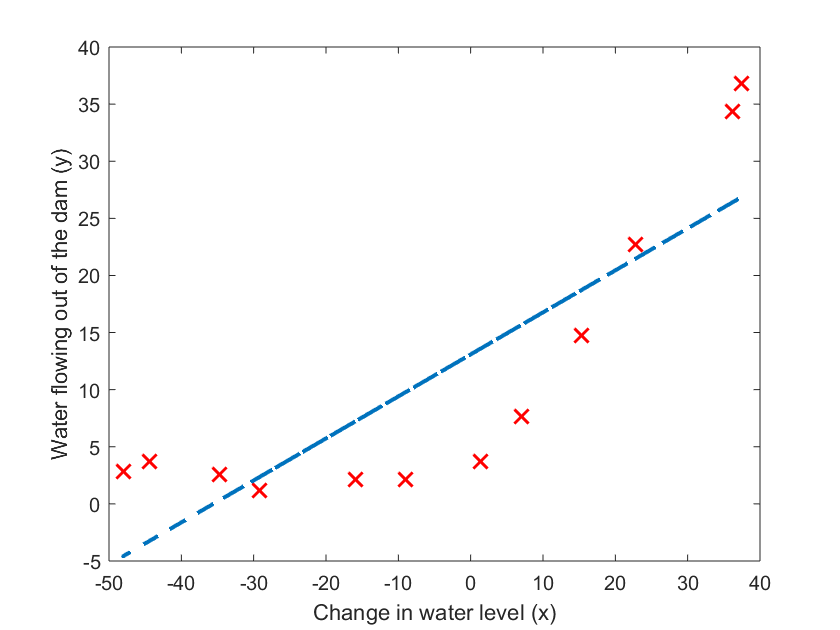

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

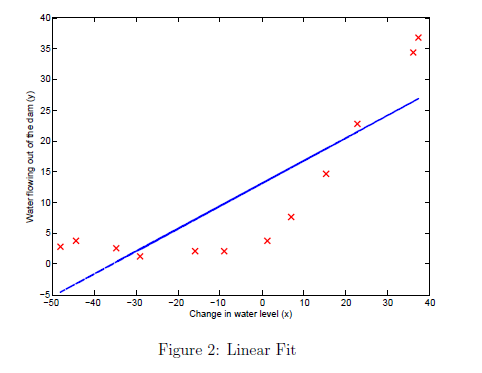

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

# 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

## 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\text{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^{m} {\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

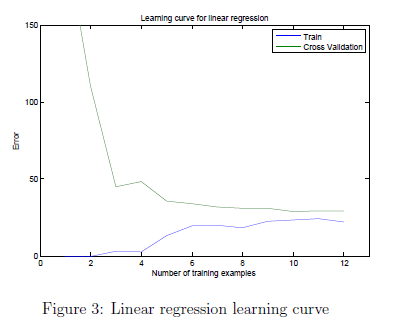

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

grad =    -2.1343
   34.0140


grad =    -1.6662
   26.5535


grad =    -0.7299
   11.6325


Iteration     1 | Cost: 2.663868e-01


grad =     3.3766
  -53.8125


grad = 	1.0e+-13 *

   -0.0089
    0.1415


Iteration     2 | Cost: 3.944305e-31


grad = 	1.0e+-11 *

    0.0170
   -0.2704


grad = 	1.0e+-12 *

    0.0164
   -0.2619


grad = 	1.0e+-13 *

    0.0089
   -0.1415


grad =      0
     0


Iteration     3 | Cost: 0.000000e+00


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =   -12.3370
 -367.6732


grad =    -1.6538
   34.1090


grad =    -0.9935
   17.9472


grad =    -0.2598
   -0.0126


Iteration     1 | Cost: 4.282328e-01


grad =    -0.2561
   -0.0124


grad =    -0.2487
   -0.0121


grad =    -0.2264
   -0.0110


grad =    -0.1596
   -0.0077


grad =     0.0144
   -0.7729


Iteration     2 | Cost: 2.397398e-29


grad =    -0.0221
    0.5405


grad =    -0.0221
    0.5405


grad =    -0.0221
    0.5404


grad =    -0.0221
    0.5398


grad =    -0.0219
    0.5331


grad =    -0.0207
    0.4641


grad =    -0.1887
    0.5135


Iteration     3 | Cost: 1.781100e-29


grad =    -0.0289
    0.3133


grad =    -0.0266
    0.2486


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =    -0.0222
    0.1484


grad =     0.0335
   -0.8242


grad =     0.0315
   -0.8136


grad =     0.0144
   -0.7729


grad =    -0.0122
   -0.1135


grad =    -0.1443
   -0.4877


Iteration     5 | Cost: 1.707144e-29


grad =    -0.1887
    0.5135


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.0110
    0.2656


grad =    -0.0125
    0.2660


grad =    -0.0255
    0.2162


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -0.1443
   -0.4877


grad =    -9.9193
 -197.7035


grad =   -12.5556
 -391.7409


grad =   -12.5630
 -389.6896


grad =   -12.5780
 -385.5869


grad =   -12.6229
 -373.2788


grad =   -12.7576
 -336.3547


grad =   -13.1617
 -225.5823


grad =   -13.9863
    0.4483


Iteration     1 | Cost: 1.021540e+02


grad =   -12.2625
    0.3930


grad =    -8.8149
    0.2825


grad =     0.0200
    0.2880


Iteration     2 | Cost: 3.286595e+00


grad =     0.0009
   -0.2339


grad =     0.0006
   -0.1559


grad =     0.0005
   -0.1403


grad =     0.0005
   -0.1403


grad =     0.0005
   -0.1401


grad =     0.0007
   -0.1374


grad =     0.0054
   -0.9021


grad =     0.0234
   -0.6426


grad =     0.0219
   -0.2612


grad =     0.0201
    0.2290


grad =     0.0200
    0.2750


grad =     0.0200
    0.2880


grad =     0.0200
    0.2880


grad =     0.0200
    0.2880


grad =     0.0200
    0.2880


grad =     0.0200
    0.2880


grad =     0.0200
    0.2880


grad =     0.0200
    0.2880


grad =     0.0200
    0.2880


grad =     0.0200
    0.2880


grad =     0.0200
    0.2880


grad =     0.0009
   -0.2314


grad =     0.0010
   -0.2288


grad =     0.0028
   -0.2025


grad =     0.0025
   -0.1200


grad =     0.0204
    0.1483


grad =     0.0228
   -0.5270


grad =     0.0220
   -0.2628


grad =     0.2123
   -0.8683


Iteration     4 | Cost: 3.286595e+00


grad =     0.0016
    0.1109


grad =     0.0182
    0.6909


grad =     0.2085
   -0.2003


grad =     0.2123
   -0.8683


grad =     0.2106
   -0.5352


grad =     0.2123
   -0.8683


grad =     0.2115
   -0.7044


grad =     0.2123
   -0.8683


grad =     0.2108
   -0.8310


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =    -0.0026
    0.6983


grad =    -0.0007
    0.6903


grad =     0.0185
    0.6118


grad =     0.0187
    0.5361


grad =     0.0195
    0.3010


grad =     0.2106
   -0.5352


grad =     0.2123
   -0.8683


grad =     0.2115
   -0.7044


grad =     0.2123
   -0.8683


grad =     0.2108
   -0.8310


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =     0.2123
   -0.8683


grad =    -1.0197
  172.4830


grad =   -18.6262
 -639.0896


grad =   -18.6149
 -637.5965


grad =   -18.5925
 -634.6104


grad =   -18.5252
 -625.6520


grad =   -18.3232
 -598.7768


grad =   -17.7173
 -518.1514


grad =   -15.8995
 -276.2751


Iteration     1 | Cost: 1.438726e+02


grad =    -9.5636
  559.5656


grad =   -13.7954
    1.3080


Iteration     2 | Cost: 1.035224e+02


grad =   -11.7967
 -157.2596


Iteration     3 | Cost: 7.536716e+01


grad =    -8.3702
  -55.1758


grad =    -3.1045
  101.7042


Iteration     4 | Cost: 1.615422e+01


grad =    15.2680
 -214.7555


grad =     0.7849
   34.7119


Iteration     5 | Cost: 3.619255e+00


grad =   -11.8838
 -525.5837


grad =    -0.4820
  -21.3176


grad =    -0.0061
   -0.2685


Iteration     6 | Cost: 2.842724e+00


grad =     0.2439
   33.0226


grad =     0.0189
    3.0606


grad =    -0.0036
    0.0644


Iteration     7 | Cost: 2.842689e+00


grad =    -0.0139
   -1.3192


grad =    -0.0046
   -0.0740


grad =    -0.0041
   -0.0002


Iteration     8 | Cost: 2.842686e+00


grad =    -0.0036
   -0.0002


grad =    -0.0028
   -0.0002


grad =    -0.4086
   -0.0227


Iteration     9 | Cost: 2.842678e+00


grad =     0.0206
    2.3220


grad =     0.0017
    0.2322


grad =    -0.0002
    0.0232


grad =    -0.0004
    0.0023


grad =    -0.4027
    0.6331


Iteration    10 | Cost: 2.842678e+00


grad =    -0.4056
    0.1992


grad =    -0.4093
   -0.3596


Iteration    11 | Cost: 2.842678e+00


grad =    -0.4069
   -0.3575


grad =    -0.4020
   -0.3533


grad =    -0.3875
   -0.3409


grad =    -0.3440
   -0.3035


grad =    -0.2134
   -0.1914


grad =    -0.0053
   -0.8108


Iteration    12 | Cost: 2.842678e+00


grad =     0.0030
    0.4557


grad =     0.0003
    0.0456


grad =     0.0000
    0.0045


grad =     0.0030
    0.4476


grad =     0.0025
    0.3746


grad =     0.0349
   -0.5648


Iteration    13 | Cost: 2.842678e+00


grad =     0.0045
    0.5589


grad =     0.0041
    0.5024


grad =     0.0037
    0.4516


grad =     0.0026
    0.2982


grad =     0.0024
    0.2679


grad =     0.0055
    0.2170


grad =     0.0053
    0.1897


grad =     0.0051
    0.1651


grad =     0.0366
   -0.3433


grad =     0.0368
   -0.3211


grad =     0.0368
   -0.3189


grad =     0.0441
    0.6658


grad =     0.0375
   -0.2204


grad =     0.0368
   -0.3091


grad =     0.0369
   -0.3081


grad =     0.0372
   -0.2642


Iteration    14 | Cost: 2.842678e+00


grad =     0.0417
    0.3597


grad =     0.0376
   -0.2019


grad =     0.0372
   -0.2580


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2608


grad =     0.0372
   -0.2633


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0372
   -0.2636


grad =     0.0019
    0.2512


grad =     0.0022
    0.2488


grad =     0.0056
    0.2250


grad =     0.3903
   -0.1281


grad =     0.0374
   -0.2391


grad =     0.0372
   -0.2617


grad =     0.0372
   -0.2640


grad =     0.0372
   -0.2642


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2643


grad =     0.0372
   -0.2642


grad =    -0.6376
  188.9972


grad =   -15.4627
 -484.2725


grad =   -15.4707
 -481.7442


grad =   -15.4866
 -476.6876


grad =   -15.5344
 -461.5176


grad =   -15.6778
 -416.0078


grad =   -16.1079
 -279.4784


grad =   -16.9901
    0.5425


Iteration     1 | Cost: 1.592641e+02


grad =   -15.6179
    0.4987


grad =   -12.8733
    0.4110


grad =    -4.6396
    0.1481


Iteration     2 | Cost: 2.404966e+01


grad =     0.0633
   -7.2034


grad =     2.1521
 -720.2100


grad =    -3.9604
  -71.8877


grad =    -4.3146
  -34.3255


Iteration     3 | Cost: 2.354137e+01


grad =    -4.3368
   -7.8988


Iteration     4 | Cost: 2.281160e+01


grad =    -4.6675
  113.1052


grad =    -4.3699
    4.2016


Iteration     5 | Cost: 2.276969e+01


grad =    -4.3547
    7.4976


grad =    -4.3244
   14.0896


grad =    -4.2336
   33.8656


Iteration     6 | Cost: 2.224060e+01


grad =    -4.0560
   21.8261


grad =    -3.7008
   -2.2531


grad =    -3.0554
  -45.9992


Iteration     7 | Cost: 1.920606e+01


grad =    -1.3156
  -37.0210


Iteration     8 | Cost: 1.475292e+01


grad =    -2.5074
  187.0033


grad =    -1.4912
   -4.0016


Iteration     9 | Cost: 1.430565e+01


grad =    -1.0569
   24.7737


Iteration    10 | Cost: 1.388881e+01


grad =    -0.3565
   13.0005


Iteration    11 | Cost: 1.327330e+01


grad =    -0.8160
  -95.5467


grad =    -0.4025
    2.1458


Iteration    12 | Cost: 1.323519e+01


grad =    -0.1896
   -6.5751


Iteration    13 | Cost: 1.319411e+01


grad =     0.2505
   -7.2955


grad =     0.0128
   -6.9064


Iteration    14 | Cost: 1.317355e+01


grad =    -0.0023
    0.3811


Iteration    15 | Cost: 1.315411e+01


grad =     0.1259
  -39.9045


grad =     0.0105
   -3.6475


grad =    -0.0010
   -0.0218


Iteration    16 | Cost: 1.315405e+01


grad =    -0.0082
    2.2791


grad =    -0.0017
    0.2083


grad =    -0.0011
    0.0012


Iteration    17 | Cost: 1.315405e+01


grad =    -0.0010
    0.0084


Iteration    18 | Cost: 1.315405e+01


grad =    -0.0009
   -0.0013


Iteration    19 | Cost: 1.315405e+01


grad =    -0.8386
    0.8732


grad =    -0.0007
    0.0051


grad =    -0.0003
    0.0138


Iteration    20 | Cost: 1.315405e+01


grad =     0.0014
   -0.0118


grad =     0.0001
    0.0082


Iteration    21 | Cost: 1.315405e+01


grad =    -0.0001
   -0.0098


grad =     0.0087
   -0.1277


Iteration    22 | Cost: 1.315405e+01


grad =    -0.0165
    0.2532


grad =    -0.0106
    0.1622


grad =    -0.0094
    0.1447


grad =    -0.0084
    0.1289


grad =    -0.0075
    0.1148


grad =    -0.0066
    0.1020


grad =    -0.0589
    0.9053


grad =    -0.0522
    0.8020


grad =    -0.0461
    0.7090


grad =    -0.0406
    0.6254


grad =    -0.0357
    0.5501


grad =    -0.0190
    0.2953


grad =    -0.0162
    0.2530


grad =    -0.0137
    0.2149


grad =    -0.0115
    0.1806


grad =    -0.0094
    0.1498


grad =    -0.0076
    0.1221


grad =    -0.0599
    0.9709


grad =    -0.0452
    0.7461


grad =    -0.0319
    0.5438


Iteration    23 | Cost: 1.315405e+01


grad =     0.0005
   -0.2522


grad =     0.0002
   -0.1654


grad =    -0.0026
   -0.1164


grad =    -0.0270
   -0.9936


grad =    -0.0291
   -0.3301


grad =    -0.0307
    0.1589


grad =    -0.0318
    0.5054


grad =    -0.0312
    0.3321


grad =    -0.0310
    0.2455


Iteration    24 | Cost: 1.315405e+01


grad =    -0.0288
   -0.4012


grad =    -0.0308
    0.1808


grad =    -0.0310
    0.2390


grad =    -0.0310
    0.2448


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2451


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2453


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2453


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2455


grad =    -0.0310
    0.2455


grad =     0.0010
   -0.3008


grad =     0.0007
   -0.2986


grad =    -0.0021
   -0.2765


grad =    -0.0025
   -0.1715


grad =    -0.0027
   -0.1012


grad =    -0.0306
    0.1196


grad =    -0.0309
    0.2329


grad =    -0.0307
    0.1762


grad =    -0.0309
    0.2272


grad =    -0.0309
    0.2323


grad =    -0.0309
    0.2297


grad =    -0.0309
    0.2284


grad =    -0.0309
    0.2296


grad =    -0.0309
    0.2297


grad =    -0.0309
    0.2296


grad =    -0.0309
    0.2297


grad =    -0.0309
    0.2297


grad =    -0.0309
    0.2297


grad =    -0.0309
    0.2297


grad =    -0.0309
    0.2297


grad =    -0.0309
    0.2297


grad =    -0.0310
    0.2455


grad =     2.4151
   79.9229


grad =   -13.2391
 -400.3995


grad =   -13.2508
 -397.8183


grad =   -13.2743
 -392.6559


grad =   -13.3447
 -377.1687


grad =   -13.5558
 -330.7071


grad =   -14.1892
 -191.3223


Iteration     1 | Cost: 1.531141e+02


grad =   -16.1263
  242.7120


grad =   -15.0511
    1.7902


Iteration     2 | Cost: 1.350947e+02


grad =   -12.0065
 -155.2224


Iteration     3 | Cost: 1.137334e+02


grad =   -10.3357
  -86.8539


grad =    -6.9942
   49.8831


Iteration     4 | Cost: 4.404199e+01


grad =     7.4075
 -464.3988


grad =    -3.1398
  -87.7551


Iteration     5 | Cost: 2.957435e+01


grad =     9.6593
 -259.3547


grad =    -1.0354
 -115.9691


Iteration     6 | Cost: 2.719561e+01


grad =    -0.7177
  -80.3819


grad =    -0.0822
   -9.2074


Iteration     7 | Cost: 1.949283e+01


grad =   -11.6668
  221.4645


grad =    -1.2407
   13.8598


grad =    -0.1981
   -6.9007


grad =    -0.1324
   -8.2072


Iteration     8 | Cost: 1.949128e+01


grad =    -0.1337
   -7.8265


grad =    -0.1363
   -7.0651


grad =    -0.1441
   -4.7808


grad =    -0.1610
    0.1989


Iteration     9 | Cost: 1.945708e+01


grad =    -0.1202
    0.1485


grad =    -0.0386
    0.0477


Iteration    10 | Cost: 1.944472e+01


grad =     0.0042
   -1.0912


grad =     0.3833
 -109.0723


grad =     0.0036
  -10.8643


grad =    -0.0344
   -1.0435


grad =    -0.0382
   -0.0614


grad =    -0.0386
    0.0288


Iteration    11 | Cost: 1.944472e+01


grad =    -0.0385
    0.0254


grad =    -0.0385
    0.0186


grad =    -0.0384
   -0.0018


grad =    -0.0380
   -0.0631


Iteration    12 | Cost: 1.944471e+01


grad =    -0.0378
   -0.0505


grad =    -0.0375
   -0.0254


grad =    -0.0365
    0.0500


grad =    -0.0336
    0.2760


Iteration    13 | Cost: 1.944453e+01


grad =    -0.0270
   -0.0221


grad =    -0.0190
   -0.3846


Iteration    14 | Cost: 1.944425e+01


grad =     0.0134
   -0.6615


grad =    -0.0020
   -0.5298


Iteration    15 | Cost: 1.944411e+01


grad =     0.0000
    0.0022


Iteration    16 | Cost: 1.944396e+01


grad =     0.0011
   -0.2405


grad =     0.0001
   -0.0220


grad =     0.0203
   -0.1785


Iteration    17 | Cost: 1.944396e+01


grad =    -0.0001
    0.0191


grad =     0.0000
    0.0017


grad =     0.1936
    0.1427


Iteration    18 | Cost: 1.944396e+01


grad =     0.1723
    0.9735


grad =     0.0130
    0.2635


Iteration    19 | Cost: 1.944396e+01


grad =     0.1080
    0.4636


Iteration    20 | Cost: 1.944396e+01


grad =     0.0000
   -0.0021


grad =     0.0117
   -0.1673


grad =     0.1101
   -0.0255


Iteration    21 | Cost: 1.944396e+01


grad =     0.1081
   -0.0249


grad =     0.1040
   -0.0236


grad =     0.9162
   -0.1982


grad =     0.5455
   -0.0844


Iteration    22 | Cost: 1.944396e+01


grad =    -0.0000
    0.0038


grad =     0.0026
    0.3800


grad =     0.0517
    0.3724


grad =     0.0533
    0.1606


Iteration    23 | Cost: 1.944396e+01


grad =     0.5342
    0.7704


grad =     0.5365
   -0.9001


Iteration    24 | Cost: 1.944396e+01


grad =     0.5175
    0.3549


grad =     0.0480
    0.2865


Iteration    25 | Cost: 1.944396e+01


grad =     0.0438
    0.2084


grad =     0.3545
    0.5212


grad =     0.0110
   -0.4071


Iteration    26 | Cost: 1.944396e+01


grad =    -0.0109
    0.2722


grad =    -0.0176
   -0.7545


Iteration    27 | Cost: 1.944396e+01


grad =     0.0047
    0.1489


grad =     0.0312
    0.8097


grad =     0.0330
   -0.8338


Iteration    28 | Cost: 1.944396e+01


grad =    -0.0195
    0.6147


grad =    -0.0165
    0.5397


grad =     0.0743
   -0.3094


Iteration    29 | Cost: 1.944396e+01


grad =    -0.0018
    0.5215


grad =     0.0049
    0.4936


grad =     0.0718
    0.2151


grad =     0.7322
   -0.7814


grad =     0.0742
   -0.2863


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.2967


grad =     0.0743
   -0.3061


grad =     0.0743
   -0.3070


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =     0.0743
   -0.3071


grad =    -0.0015
    0.3179


grad =    -0.0008
    0.3151


grad =     0.0059
    0.2872


grad =     0.7280
    0.0872


Iteration    31 | Cost: 1.944396e+01


grad =     0.7148
    0.0405


grad =     0.7267
    0.0825


grad =     0.7279
    0.0867


grad =     0.7280
    0.0871


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.7280
    0.0872


grad =     0.0041
   -0.8667


grad =     0.0696
   -0.8588


Iteration    33 | Cost: 1.944396e+01


grad =     0.0058
   -0.1272


Iteration    34 | Cost: 1.944396e+01


grad =     0.0547
   -0.9304


grad =     0.0471
   -0.2482


Iteration    35 | Cost: 1.944396e+01


grad =     0.0016
    0.6246


grad =     0.0027
    0.4036


grad =     0.0451
    0.1802


grad =     0.4622
   -0.5478


Iteration    36 | Cost: 1.944396e+01


grad =     0.0443
    0.2145


grad =     0.4603
   -0.2785


grad =     0.4620
   -0.5209


grad =     0.4612
   -0.3997


grad =     0.4620
   -0.5088


grad =     0.4616
   -0.4543


grad =     0.4619
   -0.5033


grad =     0.4617
   -0.4788


grad =     0.4619
   -0.5009


grad =     0.4619
   -0.5031


grad =     0.4619
   -0.5033


grad =     0.4619
   -0.5033


grad =     0.4619
   -0.5033


grad =     0.4619
   -0.5033


grad =     0.4619
   -0.5033


grad =     0.4619
   -0.5033


grad =     0.4619
   -0.5033


grad =     0.4619
   -0.5033


grad =     0.4619
   -0.5033


grad =     0.4619
   -0.5033


grad =     0.4619
   -0.5033


grad =    -0.0024
    0.5225


grad =     0.0018
    0.5175


grad =     0.0434
    0.4682


grad =     0.4594
   -0.0248


grad =     0.4620
   -0.4955


grad =     0.4622
   -0.5426


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5450


grad =     0.4622
   -0.5471


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5473


grad =     0.4622
   -0.5478


grad =     0.5739
   94.3699


grad =   -13.4493
 -375.3684


grad =   -13.4542
 -372.9196


grad =   -13.4639
 -368.0221


grad =   -13.4932
 -353.3293


grad =   -13.5811
 -309.2512


grad =   -13.8449
 -177.0168


Iteration     1 | Cost: 1.383936e+02


grad =   -14.6360
  239.9611


grad =   -14.1841
    1.7809


Iteration     2 | Cost: 1.210275e+02


grad =   -11.4614
 -147.2588


Iteration     3 | Cost: 1.013004e+02


grad =    -9.4248
  -89.1608


grad =    -5.3518
   27.0351


Iteration     4 | Cost: 3.457729e+01


grad =    11.6615
 -712.9905


grad =    -3.2323
  -65.1545


Iteration     5 | Cost: 2.808710e+01


grad =     5.2674
 -267.7064


grad =    -2.2315
  -89.0050


Iteration     6 | Cost: 2.732288e+01


grad =    -1.9954
  -79.5897


grad =    -1.5233
  -60.7592


grad =    -0.1070
   -4.2674


Iteration     7 | Cost: 2.011513e+01


grad =   -11.1721
  290.5375


grad =    -1.2135
   25.2131


grad =    -0.2176
   -1.3194


grad =    -0.1181
   -3.9726


Iteration     8 | Cost: 2.011508e+01


grad =    -0.1181
   -3.9386


grad =    -0.1181
   -3.8706


grad =    -0.1183
   -3.6666


grad =    -0.1189
   -3.0544


grad =    -0.1206
   -1.2180


Iteration     9 | Cost: 2.010693e+01


grad =    -0.1662
   10.1650


grad =    -0.1251
   -0.0797


Iteration    10 | Cost: 2.010640e+01


grad =    -0.1220
    2.3681


grad =    -0.1245
    0.3775


Iteration    11 | Cost: 2.010629e+01


grad =    -0.1226
    0.4533


grad =    -0.1187
    0.6049


grad =    -0.1071
    1.0599


grad =    -0.0827
    2.0094


Iteration    12 | Cost: 2.010382e+01


grad =    -0.0442
    1.0732


grad =     0.0056
    0.2144


Iteration    13 | Cost: 2.009852e+01


grad =    -0.0077
   -0.3011


grad =    -0.0051
   -0.1996


grad =    -0.0046
   -0.1803


grad =     0.0045
    0.1257


Iteration    14 | Cost: 2.009852e+01


grad =     0.0004
   -0.2005


grad =     0.0003
   -0.1330


grad =     0.0003
   -0.1196


grad =     0.0007
   -0.1083


grad =     0.4774
    0.4828


grad =     0.0046
    0.1137


grad =     0.0045
    0.1245


grad =     0.0045
    0.1189


grad =     0.0045
    0.1162


grad =     0.0045
    0.1145


grad =     0.0045
    0.1140


grad =     0.0046
    0.1137


grad =     0.0045
    0.1140


grad =     0.0045
    0.1140


grad =     0.0045
    0.1140


grad =     0.0045
    0.1140


grad =     0.0045
    0.1140


grad =     0.0045
    0.1140


grad =     0.0045
    0.1140


grad =     0.0045
    0.1140


grad =     0.0045
    0.1140


grad =     0.0002
   -0.1048


grad =     0.0014
   -0.6977


grad =     0.0018
   -0.6864


grad =     0.0059
   -0.5730


grad =     0.0054
   -0.3160


grad =     0.0461
    0.8134


grad =     0.0045
    0.1211


grad =     0.0046
    0.1013


grad =     0.0045
    0.1191


grad =     0.0046
    0.1100


grad =     0.0046
    0.1055


grad =     0.0046
    0.1035


grad =     0.0046
    0.1022


grad =     0.0046
    0.1035


grad =     0.0046
    0.1029


grad =     0.0046
    0.1029


grad =     0.0046
    0.1029


grad =     0.0046
    0.1029


grad =     0.0046
    0.1029


grad =     0.0046
    0.1029


grad =     0.0046
    0.1029


grad =     0.0045
    0.1257


grad =    -0.4775
   80.7894


grad =   -12.0949
 -317.1063


grad =   -12.1136
 -314.0968


grad =   -12.1510
 -308.0778


grad =   -12.2632
 -290.0207


grad =   -12.5997
 -235.8496


grad =   -13.6094
  -73.3361


Iteration     1 | Cost: 1.237772e+02


grad =   -18.8212
  861.7909


grad =   -14.1306
   20.1766


Iteration     2 | Cost: 1.202532e+02


grad =   -12.5862
 -185.5614


grad =   -13.8485
  -17.4008


Iteration     3 | Cost: 1.195134e+02


grad =   -13.7855
  -12.1984


grad =   -13.6595
   -1.7937


grad =   -13.2816
   29.4206


grad =   -12.1479
  123.0635


Iteration     4 | Cost: 9.334231e+01


grad =    -9.2801
   12.8044


grad =    -5.6567
 -126.5071


Iteration     5 | Cost: 4.813526e+01


grad =     7.3513
 -107.6199


grad =     2.3358
 -114.9022


Iteration     6 | Cost: 2.643724e+01


grad =    -1.2789
  336.1735


grad =     1.3953
    2.4689


Iteration     7 | Cost: 1.920971e+01


grad =     0.7719
    6.9084


grad =     0.0154
   12.2956


Iteration     8 | Cost: 1.825636e+01


grad =    -0.1607
 -128.0939


grad =    -0.0022
   -1.7434


Iteration     9 | Cost: 1.817454e+01


grad =    -0.6556
  102.8080


grad =    -0.0675
    8.7118


grad =    -0.0131
    0.0000


Iteration    10 | Cost: 1.817295e+01


grad =    -0.0118
    0.0000


grad =    -0.0091
    0.0000


grad =    -0.0012
    0.0000


Iteration    11 | Cost: 1.817286e+01


grad =     0.0144
   -0.8277


grad =     0.0003
   -0.0828


grad =    -0.0010
   -0.0132


Iteration    12 | Cost: 1.817286e+01


grad =    -0.0010
    0.0008


Iteration    13 | Cost: 1.817286e+01


grad =    -0.0008
   -0.0020


grad =    -0.0004
   -0.0074


Iteration    14 | Cost: 1.817286e+01


grad =    -0.0002
    0.0415


grad =    -0.0004
    0.0037


Iteration    15 | Cost: 1.817286e+01


grad =     0.0001
    0.0146


grad =    -0.0002
    0.0075


Iteration    16 | Cost: 1.817286e+01


grad =    -0.0001
    0.0030


Iteration    17 | Cost: 1.817286e+01


grad =    -0.0003
   -0.0200


grad =    -0.1024
    0.7327


Iteration    18 | Cost: 1.817286e+01


grad =    -0.0001
   -0.0018


grad =    -0.0720
   -0.9284


Iteration    19 | Cost: 1.817286e+01


grad =    -0.0000
   -0.0017


Iteration    20 | Cost: 1.817286e+01


grad =    -0.0016
   -0.2975


Iteration    21 | Cost: 1.817286e+01


grad =    -0.0004
    0.0104


grad =    -0.0420
    0.7760


grad =    -0.0056
   -0.1901


Iteration    22 | Cost: 1.817286e+01


grad =    -0.0579
   -0.9756


grad =    -0.0601
    0.2622


Iteration    23 | Cost: 1.817286e+01


grad =     0.0222
    0.1682


Iteration    24 | Cost: 1.817286e+01


grad =     0.0000
   -0.0023


grad =     0.0033
   -0.2169


grad =     0.2331
   -0.6553


Iteration    25 | Cost: 1.817286e+01


grad =     0.0230
   -0.5977


grad =     0.0233
   -0.1514


Iteration    26 | Cost: 1.817286e+01


grad =     0.0229
   -0.1226


grad =     0.2227
   -0.6506


grad =     0.2129
    0.2015


Iteration    27 | Cost: 1.817286e+01


grad =     0.0203
   -0.1443


Iteration    28 | Cost: 1.817286e+01


grad =     0.0179
   -0.2092


grad =     0.0129
   -0.3391


Iteration    29 | Cost: 1.817286e+01


grad =     0.0043
   -0.1738


Iteration    30 | Cost: 1.817286e+01


grad =     0.0131
    0.9053


grad =     0.0520
   -0.6590


Iteration    31 | Cost: 1.817286e+01


grad =     0.0313
    0.4182


Iteration    32 | Cost: 1.817286e+01


grad =    -0.0120
   -0.2879


Iteration    33 | Cost: 1.817286e+01


grad =    -0.0037
    0.1834


grad =    -0.0038
    0.1808


grad =    -0.0049
    0.1549


grad =    -0.0365
    0.9228


grad =    -0.0341
    0.8017


grad =    -0.0264
    0.4238


grad =    -0.0134
   -0.2167


Iteration    34 | Cost: 1.817286e+01


grad =    -0.0135
   -0.1916


grad =    -0.0136
   -0.1414


grad =    -0.1395
    0.0913


Iteration    35 | Cost: 1.817286e+01


grad =    -0.0085
   -0.1638


Iteration    36 | Cost: 1.817286e+01


grad =    -0.0017
   -0.1774


grad =    -0.0078
   -0.1652


grad =    -0.0048
   -0.1713


grad =    -0.0075
   -0.1658


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0078
   -0.1652


grad =    -0.0010
    0.1577


grad =    -0.0011
    0.1562


grad =    -0.0018
    0.1415


grad =    -0.9508
   -0.5962


grad =    -0.0086
   -0.1480


grad =    -0.0907
   -0.7699


grad =    -0.0087
   -0.1409


grad =    -0.0086
   -0.1473


grad =    -0.0086
   -0.1479


grad =    -0.0086
   -0.1476


grad =    -0.0086
   -0.1479


grad =    -0.0086
   -0.1478


grad =    -0.0086
   -0.1477


grad =    -0.0086
   -0.1478


grad =    -0.0086
   -0.1478


grad =    -0.0086
   -0.1478


grad =    -0.0086
   -0.1478


grad =    -0.0086
   -0.1478


grad =    -0.0086
   -0.1478


grad =    -0.0086
   -0.1478


grad =    -0.0086
   -0.1478


grad =    -0.0085
   -0.1638


grad =    -0.0633
   67.0828


grad =   -11.1666
 -282.4496


grad =   -11.1847
 -279.4458


grad =   -11.2209
 -273.4382


grad =   -11.3294
 -255.4156


grad =   -11.6551
 -201.3475


grad =   -12.6320
  -39.1435


Iteration     1 | Cost: 1.089984e+02


grad =   -14.3841
  432.5255


grad =   -12.8749
   26.2563


Iteration     2 | Cost: 1.064701e+02


grad =   -12.1020
  -78.1213


grad =   -12.5705
  -14.8559


Iteration     3 | Cost: 1.054742e+02


grad =   -12.4194
  -14.6773


grad =   -12.1173
  -14.3203


grad =   -11.2109
  -13.2491


grad =    -8.4916
  -10.0354


grad =    -0.3339
   -0.3946


Iteration     4 | Cost: 2.266786e+01


grad =    -0.0104
    1.4176


grad =    -0.0107
    1.4172


grad =    -1.3750
  141.3658


grad =    -0.4380
   13.7815


grad =    -0.3443
    1.0230


grad =    -0.3349
   -0.2528


grad =    -0.3340
   -0.3765


Iteration     5 | Cost: 2.266786e+01


grad =    -0.3340
   -0.3760


grad =    -0.3340
   -0.3751


grad =    -0.3340
   -0.3722


grad =    -0.3341
   -0.3637


grad =    -0.3342
   -0.3382


grad =    -0.3346
   -0.2618


grad =    -0.3357
   -0.0323


grad =    -0.3375
    0.3177


Iteration     6 | Cost: 2.266758e+01


grad =    -0.3358
    0.3161


grad =    -0.3325
    0.3130


grad =    -0.3227
    0.3037


grad =    -0.2930
    0.2758


grad =    -0.2041
    0.1922


grad =     0.0033
   -0.6663


Iteration     7 | Cost: 2.260941e+01


grad =    -0.0000
    0.0031


grad =    -0.0015
    0.3064


grad =    -0.0015
    0.3058


grad =    -0.0015
    0.2998


grad =    -0.0012
    0.2398


grad =     0.0018
   -0.3598


grad =     0.0032
   -0.6356


grad =     0.0033
   -0.6632


grad =     0.0033
   -0.6660


grad =     0.0033
   -0.6662


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =    -0.0034
    0.5657


grad =    -0.0034
    0.5597


grad =    -0.0031
    0.4997


grad =    -0.0009
   -0.9995


grad =     0.0030
   -0.6096


grad =     0.0033
   -0.6606


grad =     0.0033
   -0.6657


grad =     0.0033
   -0.6662


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =     0.0033
   -0.6663


grad =    -1.3475
   63.6283


grad =   -10.4231
 -237.6420


grad =   -10.4610
 -233.6036


grad =   -10.5370
 -225.5268


grad =   -10.7647
 -201.2964


grad =   -11.4478
 -128.6054


grad =   -12.6616
    0.5553


Iteration     1 | Cost: 1.108611e+02


grad =   -11.4515
    0.5023


grad =    -9.0314
    0.3961


grad =    -1.7711
    0.0777


Iteration     2 | Cost: 2.497543e+01


grad =     0.0995
   -8.5134


grad =     8.3595
 -851.2687


grad =    -0.7580
  -85.0570


grad =    -1.6698
   -8.4358


grad =    -1.7160
   -4.5529


Iteration     3 | Cost: 2.496421e+01


grad =    -1.7467
   -0.9919


Iteration     4 | Cost: 2.494838e+01


grad =    -1.7682
    2.3369


Iteration     5 | Cost: 2.493176e+01


grad =    -1.7313
   -0.7503


grad =    -1.6851
   -4.6062


Iteration     6 | Cost: 2.490653e+01


grad =    -1.6281
   -7.1342


grad =    -1.5142
  -12.1903


grad =    -1.3187
  -20.8722


Iteration     7 | Cost: 2.474422e+01


grad =    -1.1743
  -18.5874


grad =    -0.8856
  -14.0179


grad =    -0.0195
   -0.3093


Iteration     8 | Cost: 2.326179e+01


grad =    -3.7790
  168.2896


grad =    -0.3955
   16.5506


grad =    -0.0571
    1.3767


grad =    -0.0233
   -0.1407


grad =    -0.0199
   -0.2924


grad =    -0.0196
   -0.3047


Iteration     9 | Cost: 2.326179e+01


grad =    -0.0196
   -0.3046


grad =    -0.0196
   -0.3044


grad =    -0.0197
   -0.3039


grad =    -0.0197
   -0.3025


grad =    -0.0197
   -0.2981


grad =    -0.0198
   -0.2850


grad =    -0.0202
   -0.2457


grad =    -0.0213
   -0.1279


Iteration    10 | Cost: 2.326175e+01


grad =    -0.0252
    0.2953


grad =    -0.0225
    0.0016


Iteration    11 | Cost: 2.326174e+01


grad =    -0.0215
   -0.0331


grad =    -0.0194
   -0.1026


grad =    -0.0132
   -0.3110


Iteration    12 | Cost: 2.326165e+01


grad =    -0.0087
   -0.1512


grad =    -0.0025
    0.0713


Iteration    13 | Cost: 2.326147e+01


grad =     0.1066
   -2.7980


grad =     0.0084
   -0.2156


grad =     0.0001
    0.0036


Iteration    14 | Cost: 2.326146e+01


grad =    -0.0066
   -0.2781


grad =    -0.0006
   -0.0245


grad =    -0.0036
    0.6061


Iteration    15 | Cost: 2.326146e+01


grad =     0.0268
   -0.6990


grad =     0.0241
   -0.6285


grad =     0.0237
   -0.5733


grad =     0.0213
   -0.5099


grad =     0.0139
   -0.3145


grad =     0.0089
   -0.1839


grad =     0.0054
    0.3678


grad =    -0.0030
    0.5904


grad =    -0.0040
    0.6138


grad =    -0.0035
    0.6039


grad =    -0.0033
    0.5984


grad =    -0.0033
    0.5984


grad =    -0.0033
    0.5984


grad =    -0.0033
    0.5984


grad =    -0.0033
    0.5984


grad =    -0.0033
    0.5984


grad =    -0.0033
    0.5984


grad =    -0.0033
    0.5984


grad =    -0.0033
    0.5984


grad =    -0.0033
    0.5984


grad =    -0.0033
    0.5984


grad =     0.0054
   -0.5751


grad =     0.0054
   -0.5696


grad =     0.0051
   -0.5145


grad =     0.0031
   -0.3108


grad =     0.0028
   -0.2736


grad =     0.0016
   -0.1492


grad =     0.0080
   -0.6373


grad =    -0.0026
    0.4893


grad =     0.0276
   -0.7670


Iteration    17 | Cost: 2.326146e+01


grad =    -0.0048
    0.5295


grad =    -0.0023
    0.4629


grad =    -0.0005
    0.2707


grad =     0.0242
   -0.3830


grad =     0.0267
   -0.7196


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =     0.0276
   -0.7670


grad =    -0.0070
    0.7372


grad =    -0.0067
    0.7302


grad =    -0.0044
    0.6609


grad =     0.1884
   -0.1559


grad =     0.0245
   -0.6541


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0255
   -0.6975


grad =     0.0276
   -0.7670


grad =    -0.6424
   29.9118


grad =   -10.1690
 -220.9015


grad =   -10.2032
 -216.9325


grad =   -10.2716
 -208.9946


grad =   -10.4768
 -185.1809


grad =   -11.0924
 -113.7397


grad =   -12.0773
    0.5560


Iteration     1 | Cost: 1.023394e+02


grad =   -10.7864
    0.4965


grad =    -8.2048
    0.3777


grad =    -0.4599
    0.0212


Iteration     2 | Cost: 2.443039e+01


grad =     0.0208
   -2.2687


grad =     1.6634
 -226.8495


grad =    -0.2476
  -22.6659


grad =    -0.4387
   -2.2475


grad =    -0.4569
   -0.2998


Iteration     3 | Cost: 2.443033e+01


grad =    -0.4576
   -0.2016


grad =    -0.4589
   -0.0051


grad =    -0.4630
    0.5842


Iteration     4 | Cost: 2.442972e+01


grad =    -0.4599
    0.4481


grad =    -0.4536
    0.1759


grad =    -0.4347
   -0.6407


grad =    -0.3780
   -3.0905


Iteration     5 | Cost: 2.441042e+01


grad =    -0.3471
   -1.0147


grad =    -0.2853
    3.1369


Iteration     6 | Cost: 2.435852e+01


grad =     0.0090
   -0.3905


Iteration     7 | Cost: 2.431735e+01


grad =     2.5179
  132.9863


grad =     0.2599
   12.9471


grad =     0.0341
    0.9432


grad =     0.0117
   -0.2473


Iteration     8 | Cost: 2.431733e+01


grad =     0.0098
   -0.1436


grad =     0.0059
    0.0613


Iteration     9 | Cost: 2.431727e+01


grad =    -0.0085
   -0.0881


grad =    -0.0032
    0.1683


Iteration    10 | Cost: 2.431725e+01


grad =     0.0033
   -0.1732


grad =     0.0022
   -0.1154


grad =     0.0144
   -0.7683


grad =     0.0096
   -0.5114


grad =     0.0093
   -0.4962


grad =     0.0061
   -0.3223


grad =     0.0032
   -0.1708


grad =    -0.0025
    0.1344


grad =     0.0034
   -0.1824


Iteration    11 | Cost: 2.431725e+01


grad =    -0.0016
    0.1867


grad =    -0.0013
    0.1703


grad =    -0.0007
    0.1040


grad =    -0.0033
    0.5956


grad =     0.0028
   -0.1046


grad =     0.0034
   -0.1747


grad =     0.0034
   -0.1816


grad =     0.0034
   -0.1781


grad =     0.0034
   -0.1813


grad =     0.0034
   -0.1797


grad =     0.0034
   -0.1812


grad =     0.0034
   -0.1813


grad =     0.0034
   -0.1813


grad =     0.0034
   -0.1812


grad =     0.0034
   -0.1813


grad =     0.0034
   -0.1813


grad =     0.0034
   -0.1813


grad =     0.0034
   -0.1813


grad =     0.0034
   -0.1813


grad =     0.0034
   -0.1813


grad =     0.0034
   -0.1813


grad =    -0.0014
    0.1592


grad =    -0.0009
    0.1060


grad =    -0.0009
    0.1044


grad =    -0.0058
    0.8797


grad =     0.0252
   -0.7616


Iteration    13 | Cost: 2.431725e+01


grad =     0.0003
    0.1764


grad =     0.0230
   -0.5088


grad =     0.0250
   -0.7361


grad =     0.0252
   -0.7590


grad =     0.0251
   -0.7479


grad =     0.0252
   -0.7581


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7586


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =     0.0252
   -0.7590


grad =    -0.0058
    0.6665


grad =    -0.0056
    0.6597


grad =    -0.0036
    0.4360


grad =    -0.0013
    0.3674


grad =     0.0214
   -0.3179


Iteration    15 | Cost: 2.431725e+01


grad =     0.0121
    0.7353


grad =     0.0204
   -0.2121


grad =     0.0213
   -0.3072


grad =     0.0214
   -0.3163


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3173


grad =    -0.0024
    0.2787


grad =    -0.0022
    0.2758


grad =    -0.0003
    0.2472


grad =     0.1895
   -0.3911


grad =     0.0211
   -0.2901


grad =     0.0214
   -0.3149


grad =     0.0214
   -0.3173


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =     0.0214
   -0.3179


grad =    -1.4983
   20.9449


grad =   -11.2176
 -245.6520


grad =   -11.2381
 -242.2045


grad =   -11.2790
 -235.3094


grad =   -11.4018
 -214.6242


grad =   -11.7704
 -152.5687


grad =   -12.6798
    0.5790


Iteration     1 | Cost: 1.052435e+02


grad =   -11.2240
    0.5125


grad =    -8.3124
    0.3796


grad =    -0.0012
    0.5174


Iteration     2 | Cost: 2.237391e+01


grad =     0.0027
   -0.4519


grad =     0.0027
   -0.4518


grad =     0.0018
   -0.3012


grad =     0.0012
   -0.2008


grad =     0.0008
   -0.1338


grad =     0.0053
   -0.8919


grad =     0.0035
   -0.5943


grad =     0.0024
   -0.3960


grad =     0.0016
   -0.2637


grad =     0.0010
   -0.1755


grad =     0.0007
   -0.1168


grad =     0.0046
   -0.7759


grad =     0.0031
   -0.5147


grad =     0.0030
   -0.4680


grad =     0.0019
   -0.2849


grad =     0.0012
   -0.1621


grad =     0.0001
    0.3044


grad =     0.0058
   -0.6582


grad =     0.0034
   -0.2576


Iteration     3 | Cost: 2.237391e+01


grad =    -0.0006
    0.1301


grad =    -0.0025
    0.7278


grad =    -0.0002
    0.3370


grad =     0.0002
    0.2776


grad =     0.0177
    0.1467


grad =     0.0032
   -0.2309


grad =     0.0025
   -0.1078


Iteration     4 | Cost: 2.237391e+01


grad =     0.0003
    0.2509


grad =     0.0012
    0.1037


grad =     0.1864
   -0.3244


Iteration     5 | Cost: 2.237391e+01


grad =    -0.0013
    0.4458


grad =    -0.0003
    0.2956


grad =     0.0005
    0.1951


grad =     0.0171
    0.1699


grad =     0.1839
   -0.1227


grad =     0.1850
   -0.2974


grad =     0.1840
   -0.2102


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =     0.1839
   -0.1534


grad =    -0.0008
    0.1308


grad =     0.0009
    0.1279


grad =     0.0010
    0.1147


grad =     0.0128
    0.7486


grad =     0.0147
    0.4811


grad =     0.0159
    0.3028


grad =     0.0168
    0.1835


grad =     0.0175
    0.1022


grad =     0.1782
    0.4553


grad =     0.1846
   -0.2453


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1849
   -0.3533


grad =     0.1864
   -0.3244


grad =    -1.3659
   24.1893



plot(1:m, error_train, 1:m, error_val);

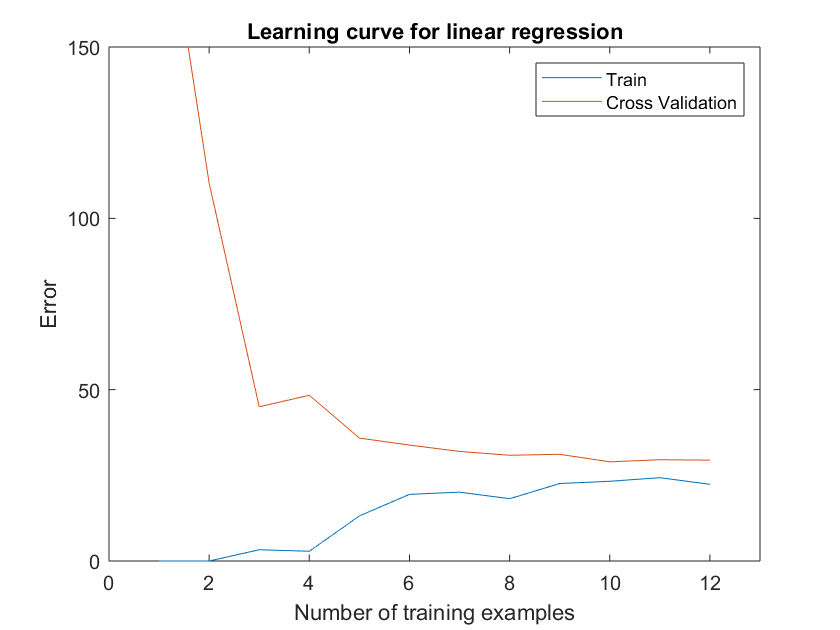

title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


# 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% % Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  



lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

grad =   -11.2176
  -10.1019
   -1.7795
   -8.3594
    0.0332
   -6.6599
    1.2410
   -5.3929
    1.9800


grad =   -11.1881
  -10.0333
   -1.8215
   -8.2855
   -0.0193
   -6.5871
    1.1835
   -5.3229
    1.9202


grad =   -11.1292
   -9.8962
   -1.9055
   -8.1378
   -0.1242
   -6.4417
    1.0684
   -5.1828
    1.8007


grad =   -10.9525
   -9.4847
   -2.1574
   -7.6947
   -0.4389
   -6.0053
    0.7232
   -4.7627
    1.4422


grad =   -10.4223
   -8.2502
   -2.9133
   -6.3652
   -1.3830
   -4.6960
   -0.3124
   -3.5022
    0.3667


grad =    -8.8317
   -4.5468
   -5.1811
   -2.3767
   -4.2154
   -0.7684
   -3.4192
    0.2791
   -2.8598


Iteration     1 | Cost: 8.273077e+01


grad =    -4.6160
   -4.6419
   -0.3218
   -3.7678
    0.5479
   -3.0907
    1.0543
   -2.6186
    1.3484


Iteration     2 | Cost: 2.687496e+01


grad =     0.6008
    8.1577
   -8.5599
   10.1042
   -9.6223
   10.6431
  -10.0327
   10.6563
  -10.1260


grad =    -2.8599
   -0.3333
   -3.0949
    0.9017
   -2.8755
    1.5323
   -2.6778
    1.8500
   -2.5141


Iteration     3 | Cost: 1.327780e+01


grad =     0.8911
    0.0898
    0.6080
    0.2747
    0.6809
    0.1232
    0.6088
   -0.0550
    0.5412


Iteration     4 | Cost: 3.455324e+00


grad =    -9.2367
    8.3804
  -20.4996
   13.1362
  -21.1557
   15.8659
  -20.7317
   17.2767
  -20.1015


grad =    -0.1217
    0.9189
   -1.5027
    1.5608
   -1.5027
    1.6975
   -1.5253
    1.6782
   -1.5231


grad =     0.4555
    0.4464
   -0.2998
    0.8279
   -0.2583
    0.8003
   -0.3091
    0.6905
   -0.3467


Iteration     5 | Cost: 2.870493e+00


grad =    -0.1865
   -0.4419
   -0.0792
   -0.0702
    0.1174
   -0.0275
    0.1612
   -0.0643
    0.1756


Iteration     6 | Cost: 2.404364e+00


grad =    -2.3873
    0.2336
   -3.1840
    1.0491
   -2.9038
    1.5308
   -2.6488
    1.7892
   -2.4498


grad =    -0.4066
   -0.3744
   -0.3897
    0.0417
   -0.1847
    0.1284
   -0.1198
    0.1210
   -0.0869


Iteration     7 | Cost: 2.372779e+00


grad =    -0.3800
   -0.4010
   -0.3161
   -0.0171
   -0.1036
    0.0560
   -0.0364
    0.0432
   -0.0036


grad =    -0.3268
   -0.4544
   -0.1689
   -0.1348
    0.0586
   -0.0886
    0.1304
   -0.1126
    0.1631


grad =    -0.1673
   -0.6143
    0.2728
   -0.4880
    0.5454
   -0.5225
    0.6308
   -0.5798
    0.6631


Iteration     8 | Cost: 1.771555e+00


grad =     0.0935
    0.2306
   -0.2668
    0.3191
   -0.0914
    0.2570
   -0.0409
    0.1733
   -0.0187


Iteration     9 | Cost: 1.210317e+00


grad =     0.5978
    0.2096
    0.3922
   -0.1400
    0.5874
   -0.3447
    0.6415
   -0.4717
    0.6547


grad =     0.3539
    0.2197
    0.0735
    0.0820
    0.2591
   -0.0537
    0.3115
   -0.1598
    0.3290


Iteration    10 | Cost: 9.411493e-01


grad =     0.2740
    0.5952
   -0.4249
    0.4283
   -0.3074
    0.3494
   -0.2614
    0.2948
   -0.2366


Iteration    11 | Cost: 7.950460e-01


grad =    -0.1248
   -0.2976
    0.1765
   -0.7739
    0.3611
   -0.8073
    0.4596
   -0.7541
    0.5076


grad =     0.2090
    0.4498
   -0.3270
    0.2325
   -0.1985
    0.1610
   -0.1439
    0.1239
   -0.1154


Iteration    12 | Cost: 7.507694e-01


grad =     0.1903
    0.2914
   -0.1606
    0.0607
   -0.0133
   -0.0196
    0.0451
   -0.0601
    0.0727


Iteration    13 | Cost: 6.855165e-01


grad =     0.0746
    0.1798
   -0.1256
   -0.0288
    0.0169
   -0.0875
    0.0724
   -0.1118
    0.0980


grad =    -0.1340
   -0.0215
   -0.0625
   -0.1902
    0.0715
   -0.2099
    0.1218
   -0.2051
    0.1438


Iteration    14 | Cost: 5.613719e-01


grad =    -0.2316
    0.5482
   -0.7397
    0.6029
   -0.7711
    0.6882
   -0.7939
    0.7378
   -0.8009


grad =    -0.1574
    0.1151
   -0.2249
   -0.0000
   -0.1306
    0.0054
   -0.0978
    0.0209
   -0.0827


Iteration    15 | Cost: 5.316066e-01


grad =    -0.1054
    0.0862
   -0.1418
   -0.0138
   -0.0756
   -0.0024
   -0.0634
    0.0161
   -0.0617


grad =    -0.0080
    0.0321
    0.0141
   -0.0395
    0.0274
   -0.0169
    0.0010
    0.0070
   -0.0222


Iteration    16 | Cost: 4.460234e-01


grad =     0.4502
    0.6693
   -1.0780
    0.9729
   -1.2046
    1.1490
   -1.2704
    1.2304
   -1.2927


grad =     0.0378
    0.0958
   -0.0951
    0.0617
   -0.0958
    0.0997
   -0.1261
    0.1293
   -0.1492


Iteration    17 | Cost: 4.398482e-01


grad =     0.0932
    0.0584
   -0.1043
    0.0492
   -0.1063
    0.0976
   -0.1365
    0.1320
   -0.1589


Iteration    18 | Cost: 4.271637e-01


grad =     0.0814
   -0.0202
   -0.0105
   -0.0472
   -0.0013
   -0.0067
   -0.0283
    0.0250
   -0.0506


Iteration    19 | Cost: 4.168413e-01


grad =    -0.0278
    0.0262
    0.0139
   -0.0169
    0.0208
    0.0089
   -0.0092
    0.0300
   -0.0338


Iteration    20 | Cost: 4.084283e-01


grad =    -0.0111
   -0.1055
    0.1375
   -0.1838
    0.1804
   -0.1750
    0.1680
   -0.1609
    0.1515


grad =    -0.0209
   -0.0276
    0.0644
   -0.0851
    0.0861
   -0.0663
    0.0632
   -0.0480
    0.0420


Iteration    21 | Cost: 4.049304e-01


grad =    -0.0097
   -0.0171
    0.0412
   -0.0749
    0.0688
   -0.0576
    0.0507
   -0.0408
    0.0328


grad =     0.0128
    0.0039
   -0.0053
   -0.0547
    0.0344
   -0.0404
    0.0257
   -0.0265
    0.0143


Iteration    22 | Cost: 3.897848e-01


grad =    -0.0755
    0.4811
   -0.4336
    0.5318
   -0.4989
    0.5861
   -0.5561
    0.6099
   -0.5878


grad =     0.0040
    0.0516
   -0.0481
    0.0040
   -0.0189
    0.0223
   -0.0325
    0.0371
   -0.0459


grad =     0.0087
    0.0261
   -0.0252
   -0.0274
    0.0096
   -0.0113
   -0.0014
    0.0031
   -0.0137


Iteration    23 | Cost: 3.892967e-01


grad =     0.0051
    0.0249
   -0.0199
   -0.0282
    0.0139
   -0.0124
    0.0021
    0.0017
   -0.0109


grad =    -0.0021
    0.0227
   -0.0092
   -0.0299
    0.0225
   -0.0146
    0.0089
   -0.0011
   -0.0052


grad =    -0.0236
    0.0159
    0.0229
   -0.0349
    0.0482
   -0.0212
    0.0294
   -0.0094
    0.0119


Iteration    24 | Cost: 3.830089e-01


grad =    -0.0197
    0.0983
   -0.0746
    0.0764
   -0.0672
    0.1012
   -0.0928
    0.1165
   -0.1124


grad =    -0.0217
    0.0561
   -0.0247
    0.0195
   -0.0081
    0.0385
   -0.0302
    0.0520
   -0.0488


Iteration    25 | Cost: 3.808647e-01


grad =    -0.0108
    0.0589
   -0.0431
    0.0353
   -0.0317
    0.0602
   -0.0559
    0.0763
   -0.0751


grad =     0.0096
    0.0640
   -0.0776
    0.0649
   -0.0758
    0.1007
   -0.1041
    0.1218
   -0.1246


Iteration    26 | Cost: 3.747040e-01


grad =     0.0276
   -0.0087
   -0.0232
   -0.0017
   -0.0192
    0.0378
   -0.0476
    0.0616
   -0.0688


Iteration    27 | Cost: 3.661580e-01


grad =    -0.0402
   -0.0888
    0.1556
   -0.1547
    0.1909
   -0.1512
    0.1735
   -0.1445
    0.1547


grad =     0.0149
   -0.0237
    0.0101
   -0.0302
    0.0200
    0.0025
   -0.0064
    0.0232
   -0.0271


Iteration    28 | Cost: 3.650093e-01


grad =     0.0057
   -0.0067
    0.0032
   -0.0162
    0.0135
    0.0137
   -0.0123
    0.0321
   -0.0326


grad =    -0.0128
    0.0272
   -0.0105
    0.0120
    0.0007
    0.0360
   -0.0242
    0.0500
   -0.0437


Iteration    29 | Cost: 3.602801e-01


grad =    -0.0213
   -0.0359
    0.0686
   -0.0752
    0.0965
   -0.0629
    0.0788
   -0.0542
    0.0621


grad =    -0.0174
   -0.0072
    0.0326
   -0.0356
    0.0529
   -0.0180
    0.0320
   -0.0068
    0.0140


Iteration    30 | Cost: 3.584005e-01


grad =    -0.0168
   -0.0115
    0.0349
   -0.0497
    0.0651
   -0.0377
    0.0504
   -0.0298
    0.0361


grad =    -0.0161
   -0.0167
    0.0375
   -0.0665
    0.0796
   -0.0614
    0.0723
   -0.0572
    0.0624


Iteration    31 | Cost: 3.542730e-01


grad =    -0.0108
    0.0565
   -0.0517
    0.0135
   -0.0092
    0.0195
   -0.0125
    0.0221
   -0.0183


Iteration    32 | Cost: 3.514101e-01


grad =     0.0582
    0.1029
   -0.1994
    0.0463
   -0.1104
    0.0413
   -0.0764
    0.0359
   -0.0566


grad =    -0.0016
    0.0627
   -0.0714
    0.0179
   -0.0227
    0.0224
   -0.0210
    0.0240
   -0.0234


Iteration    33 | Cost: 3.508596e-01


grad =    -0.0008
    0.0480
   -0.0562
    0.0006
   -0.0056
    0.0042
   -0.0032
    0.0056
   -0.0055


grad =     0.0007
    0.0211
   -0.0285
   -0.0309
    0.0257
   -0.0290
    0.0293
   -0.0279
    0.0273


Iteration    34 | Cost: 3.493046e-01


grad =     0.0028
    0.0168
   -0.0257
   -0.0309
    0.0255
   -0.0270
    0.0273
   -0.0249
    0.0243


grad =     0.0069
    0.0081
   -0.0200
   -0.0311
    0.0251
   -0.0231
    0.0233
   -0.0188
    0.0183


grad =     0.0192
   -0.0181
   -0.0030
   -0.0316
    0.0239
   -0.0112
    0.0113
   -0.0007
    0.0003


Iteration    35 | Cost: 3.307513e-01


grad =    -0.1763
    0.6743
   -0.5863
    0.7557
   -0.6593
    0.7931
   -0.7109
    0.7933
   -0.7333


grad =    -0.0003
    0.0511
   -0.0613
    0.0472
   -0.0444
    0.0692
   -0.0609
    0.0787
   -0.0731


grad =     0.0121
    0.0073
   -0.0244
   -0.0026
   -0.0012
    0.0183
   -0.0153
    0.0285
   -0.0267


Iteration    36 | Cost: 3.302370e-01


grad =    -0.0004
    0.0119
   -0.0182
   -0.0005
    0.0045
    0.0183
   -0.0102
    0.0270
   -0.0220


grad =    -0.0253
    0.0210
   -0.0057
    0.0037
    0.0159
    0.0183
    0.0001
    0.0240
   -0.0126


Iteration    37 | Cost: 3.283827e-01


grad =    -0.0119
   -0.0357
    0.0437
   -0.0625
    0.0747
   -0.0508
    0.0631
   -0.0452
    0.0521


grad =    -0.0178
   -0.0109
    0.0221
   -0.0335
    0.0490
   -0.0205
    0.0355
   -0.0149
    0.0237


Iteration    38 | Cost: 3.275156e-01


grad =    -0.0048
   -0.0161
    0.0155
   -0.0374
    0.0442
   -0.0231
    0.0324
   -0.0165
    0.0218


grad =     0.0212
   -0.0265
    0.0024
   -0.0452
    0.0347
   -0.0283
    0.0263
   -0.0197
    0.0180


Iteration    39 | Cost: 3.237392e-01


grad =     0.0123
    0.0700
   -0.0946
    0.0687
   -0.0759
    0.0911
   -0.0889
    0.1002
   -0.0979


grad =     0.0184
    0.0038
   -0.0281
   -0.0094
   -0.0001
    0.0093
   -0.0100
    0.0180
   -0.0184


Iteration    40 | Cost: 3.229208e-01


grad =     0.0001
    0.0146
   -0.0219
   -0.0010
    0.0040
    0.0150
   -0.0074
    0.0216
   -0.0169


grad =    -0.0301
    0.0324
   -0.0115
    0.0129
    0.0109
    0.0244
   -0.0032
    0.0277
   -0.0143


Iteration    41 | Cost: 3.207518e-01


grad =    -0.0357
   -0.0398
    0.0724
   -0.0747
    0.1041
   -0.0697
    0.0929
   -0.0685
    0.0821


grad =    -0.0323
    0.0036
    0.0220
   -0.0221
    0.0481
   -0.0131
    0.0351
   -0.0107
    0.0242


Iteration    42 | Cost: 3.198866e-01


grad =    -0.0259
   -0.0005
    0.0196
   -0.0248
    0.0461
   -0.0149
    0.0338
   -0.0118
    0.0233


grad =    -0.0130
   -0.0087
    0.0148
   -0.0303
    0.0421
   -0.0183
    0.0310
   -0.0139
    0.0215


grad =     0.0256
   -0.0334
    0.0005
   -0.0469
    0.0302
   -0.0287
    0.0227
   -0.0202
    0.0162


grad =     0.0878
   -0.0731
   -0.0224
   -0.0735
    0.0111
   -0.0454
    0.0094
   -0.0303
    0.0077


Iteration    43 | Cost: 3.037558e-01


grad =     0.0804
    0.1264
   -0.2284
    0.1701
   -0.2293
    0.2112
   -0.2404
    0.2269
   -0.2421


grad =     0.0848
    0.0076
   -0.1057
    0.0250
   -0.0861
    0.0584
   -0.0916
    0.0737
   -0.0933


Iteration    44 | Cost: 2.972320e-01


grad =     0.0607
    0.0154
   -0.0860
    0.0293
   -0.0705
    0.0577
   -0.0779
    0.0691
   -0.0805


grad =     0.0125
    0.0310
   -0.0465
    0.0379
   -0.0392
    0.0563
   -0.0506
    0.0597
   -0.0548


grad =    -0.0702
    0.0579
    0.0212
    0.0527
    0.0144
    0.0538
   -0.0036
    0.0438
   -0.0106


Iteration    45 | Cost: 2.552596e-01


grad =     0.1286
   -0.7072
    0.5756
   -0.7910
    0.6778
   -0.8005
    0.7182
   -0.7979
    0.7398


grad =    -0.0504
   -0.0186
    0.0767
   -0.0316
    0.0808
   -0.0316
    0.0686
   -0.0404
    0.0644


Iteration    46 | Cost: 2.512670e-01


grad =    -0.0128
   -0.0296
    0.0373
   -0.0315
    0.0441
   -0.0233
    0.0367
   -0.0271
    0.0366


Iteration    47 | Cost: 2.450939e-01


grad =    -0.0288
    0.1818
   -0.1658
    0.2139
   -0.1878
    0.2327
   -0.2061
    0.2298
   -0.2092


grad =    -0.0146
   -0.0061
    0.0148
   -0.0042
    0.0183
    0.0051
    0.0097
    0.0014
    0.0093


Iteration    48 | Cost: 2.446274e-01


grad =     0.0003
   -0.0035
   -0.0047
    0.0018
   -0.0000
    0.0138
   -0.0069
    0.0118
   -0.0059


Iteration    49 | Cost: 2.440357e-01


grad =     0.0134
   -0.0403
    0.0236
   -0.0429
    0.0364
   -0.0331
    0.0336
   -0.0352
    0.0366


grad =     0.0050
   -0.0166
    0.0054
   -0.0141
    0.0129
   -0.0029
    0.0075
   -0.0049
    0.0092


Iteration    50 | Cost: 2.438698e-01


grad =     0.0106
   -0.0192
    0.0037
   -0.0185
    0.0135
   -0.0078
    0.0097
   -0.0099
    0.0124


grad =     0.0192
   -0.0230
    0.0011
   -0.0252
    0.0144
   -0.0153
    0.0131
   -0.0174
    0.0174


Iteration    51 | Cost: 2.434506e-01


grad =     0.0204
    0.0007
   -0.0248
    0.0003
   -0.0127
    0.0107
   -0.0136
    0.0083
   -0.0085


Iteration    52 | Cost: 2.431036e-01


grad =     0.0088
    0.0134
   -0.0261
    0.0077
   -0.0130
    0.0146
   -0.0131
    0.0101
   -0.0076


Iteration    53 | Cost: 2.425132e-01


grad =     0.0035
   -0.0147
    0.0093
   -0.0271
    0.0256
   -0.0229
    0.0263
   -0.0284
    0.0316


grad =     0.0063
    0.0004
   -0.0097
   -0.0084
    0.0048
   -0.0027
    0.0051
   -0.0077
    0.0105


Iteration    54 | Cost: 2.423193e-01


grad =    -0.0023
    0.0030
   -0.0058
   -0.0054
    0.0065
    0.0002
    0.0052
   -0.0050
    0.0097


grad =    -0.0155
    0.0069
    0.0002
   -0.0008
    0.0091
    0.0046
    0.0055
   -0.0009
    0.0085


Iteration    55 | Cost: 2.418300e-01


grad =    -0.0039
    0.0178
   -0.0207
    0.0198
   -0.0182
    0.0307
   -0.0246
    0.0281
   -0.0228


Iteration    56 | Cost: 2.415535e-01


grad =     0.0201
   -0.0088
   -0.0095
    0.0019
   -0.0124
    0.0197
   -0.0221
    0.0219
   -0.0222


grad =     0.0060
    0.0068
   -0.0160
    0.0124
   -0.0158
    0.0261
   -0.0236
    0.0255
   -0.0225


Iteration    57 | Cost: 2.413503e-01


grad =     0.0045
   -0.0041
   -0.0028
   -0.0016
   -0.0006
    0.0108
   -0.0078
    0.0097
   -0.0065


Iteration    58 | Cost: 2.410882e-01


grad =    -0.0004
   -0.0121
    0.0113
   -0.0142
    0.0156
   -0.0041
    0.0092
   -0.0063
    0.0106


Iteration    59 | Cost: 2.408594e-01


grad =    -0.0034
    0.0026
   -0.0016
    0.0013
    0.0015
    0.0112
   -0.0051
    0.0086
   -0.0035


Iteration    60 | Cost: 2.406100e-01


grad =    -0.0040
   -0.0004
    0.0020
   -0.0052
    0.0076
    0.0031
    0.0026
   -0.0003
    0.0049


grad =    -0.0050
   -0.0057
    0.0085
   -0.0169
    0.0186
   -0.0114
    0.0162
   -0.0161
    0.0200


Iteration    61 | Cost: 2.400439e-01


grad =    -0.0048
    0.0222
   -0.0231
    0.0034
   -0.0069
    0.0049
   -0.0038
   -0.0021
    0.0039


grad =    -0.0049
    0.0064
   -0.0052
   -0.0081
    0.0075
   -0.0043
    0.0075
   -0.0100
    0.0130


Iteration    62 | Cost: 2.397980e-01


grad =    -0.0006
    0.0211
   -0.0240
    0.0150
   -0.0168
    0.0225
   -0.0197
    0.0185
   -0.0154


grad =    -0.0029
    0.0134
   -0.0142
    0.0029
   -0.0041
    0.0084
   -0.0054
    0.0036
   -0.0005


Iteration    63 | Cost: 2.396810e-01


grad =     0.0004
    0.0055
   -0.0076
   -0.0031
    0.0013
    0.0036
   -0.0011
   -0.0004
    0.0031


Iteration    64 | Cost: 2.395195e-01


grad =    -0.0033
   -0.0030
    0.0036
   -0.0138
    0.0134
   -0.0079
    0.0111
   -0.0122
    0.0152


Iteration    65 | Cost: 2.393797e-01


grad =    -0.0050
    0.0018
   -0.0008
   -0.0079
    0.0078
   -0.0016
    0.0051
   -0.0058
    0.0090


grad =    -0.0085
    0.0114
   -0.0097
    0.0039
   -0.0033
    0.0110
   -0.0069
    0.0070
   -0.0034


Iteration    66 | Cost: 2.389002e-01


grad =    -0.0084
    0.0015
    0.0014
   -0.0065
    0.0073
    0.0008
    0.0031
   -0.0028
    0.0062


grad =    -0.0084
   -0.0183
    0.0236
   -0.0272
    0.0284
   -0.0196
    0.0232
   -0.0225
    0.0254


Iteration    67 | Cost: 2.376436e-01


grad =    -0.0055
   -0.0270
    0.0330
   -0.0303
    0.0304
   -0.0189
    0.0212
   -0.0194
    0.0212


Iteration    68 | Cost: 2.360935e-01


grad =    -0.0031
    0.0186
   -0.0175
    0.0249
   -0.0267
    0.0399
   -0.0380
    0.0404
   -0.0382


grad =    -0.0043
   -0.0038
    0.0073
   -0.0022
    0.0013
    0.0110
   -0.0089
    0.0111
   -0.0090


Iteration    69 | Cost: 2.355578e-01


grad =     0.0071
    0.0017
   -0.0010
   -0.0001
   -0.0032
    0.0112
   -0.0108
    0.0102
   -0.0092


grad =     0.0218
    0.0087
   -0.0115
    0.0026
   -0.0091
    0.0115
   -0.0132
    0.0091
   -0.0094


Iteration    70 | Cost: 2.343356e-01


grad =     0.0011
   -0.0681
    0.0767
   -0.1004
    0.0980
   -0.1032
    0.1022
   -0.1103
    0.1092


grad =     0.0187
   -0.0027
    0.0016
   -0.0127
    0.0069
   -0.0055
    0.0040
   -0.0086
    0.0083


Iteration    71 | Cost: 2.341539e-01


grad =     0.0067
    0.0018
   -0.0011
   -0.0090
    0.0045
   -0.0025
    0.0019
   -0.0061
    0.0064


grad =    -0.0061
    0.0065
   -0.0039
   -0.0050
    0.0020
    0.0008
   -0.0003
   -0.0035
    0.0044


Iteration    72 | Cost: 2.337793e-01


grad =    -0.0017
    0.0237
   -0.0245
    0.0196
   -0.0234
    0.0283
   -0.0278
    0.0251
   -0.0238


Iteration    73 | Cost: 2.335160e-01


grad =     0.0051
    0.0215
   -0.0247
    0.0226
   -0.0269
    0.0336
   -0.0331
    0.0315
   -0.0301


grad =     0.0146
    0.0185
   -0.0250
    0.0270
   -0.0317
    0.0411
   -0.0405
    0.0405
   -0.0389


Iteration    74 | Cost: 2.326140e-01


grad =     0.0152
   -0.0138
    0.0101
   -0.0096
    0.0064
    0.0028
   -0.0019
    0.0020
   -0.0006


Iteration    75 | Cost: 2.317379e-01


grad =    -0.0265
   -0.0068
    0.0159
   -0.0073
    0.0138
    0.0011
    0.0062
   -0.0024
    0.0078


Iteration    76 | Cost: 2.309727e-01


grad =    -0.0319
    0.0513
   -0.0472
    0.0573
   -0.0523
    0.0667
   -0.0591
    0.0623
   -0.0559


grad =    -0.0281
    0.0110
   -0.0034
    0.0125
   -0.0064
    0.0212
   -0.0138
    0.0174
   -0.0117


Iteration    77 | Cost: 2.306963e-01


grad =    -0.0224
    0.0081
   -0.0025
    0.0080
   -0.0036
    0.0161
   -0.0097
    0.0119
   -0.0069


grad =    -0.0108
    0.0022
   -0.0006
   -0.0009
    0.0022
    0.0057
   -0.0015
    0.0009
    0.0026


Iteration    78 | Cost: 2.294600e-01


grad =     0.3173
   -0.1412
    0.0691
   -0.1215
    0.0638
   -0.0900
    0.0530
   -0.0755
    0.0518


grad =     0.0220
   -0.0121
    0.0063
   -0.0130
    0.0084
   -0.0039
    0.0039
   -0.0067
    0.0075


grad =    -0.0068
    0.0005
    0.0002
   -0.0024
    0.0029
    0.0045
   -0.0009
    0.0000
    0.0032


Iteration    79 | Cost: 2.294501e-01


grad =    -0.0056
    0.0008
   -0.0005
   -0.0020
    0.0023
    0.0050
   -0.0015
    0.0005
    0.0026


grad =    -0.0032
    0.0013
   -0.0018
   -0.0013
    0.0010
    0.0058
   -0.0027
    0.0014
    0.0015


grad =     0.0039
    0.0028
   -0.0057
    0.0009
   -0.0029
    0.0084
   -0.0065
    0.0043
   -0.0021


Iteration    80 | Cost: 2.293494e-01


grad =     0.0104
   -0.0111
    0.0077
   -0.0158
    0.0127
   -0.0091
    0.0101
   -0.0134
    0.0148


grad =     0.0069
   -0.0036
    0.0004
   -0.0068
    0.0042
    0.0004
    0.0011
   -0.0038
    0.0057


Iteration    81 | Cost: 2.293085e-01


grad =     0.0077
   -0.0043
    0.0011
   -0.0078
    0.0052
   -0.0008
    0.0022
   -0.0050
    0.0068


grad =     0.0092
   -0.0058
    0.0025
   -0.0100
    0.0070
   -0.0032
    0.0043
   -0.0075
    0.0089


grad =     0.0138
   -0.0101
    0.0067
   -0.0164
    0.0125
   -0.0103
    0.0105
   -0.0147
    0.0155


grad =     0.0275
   -0.0231
    0.0193
   -0.0356
    0.0289
   -0.0317
    0.0291
   -0.0366
    0.0353


Iteration    82 | Cost: 2.280315e-01


grad =     0.0369
   -0.0019
   -0.0043
   -0.0143
    0.0043
   -0.0101
    0.0053
   -0.0150
    0.0123


grad =     0.0479
    0.0230
   -0.0321
    0.0108
   -0.0246
    0.0152
   -0.0228
    0.0104
   -0.0147


Iteration    83 | Cost: 2.256266e-01


grad =     0.0425
    0.0262
   -0.0279
   -0.0014
   -0.0152
   -0.0029
   -0.0091
   -0.0095
    0.0016


Iteration    84 | Cost: 2.224094e-01


grad =    -0.0138
   -0.0202
    0.0335
   -0.0522
    0.0464
   -0.0557
    0.0501
   -0.0627
    0.0582


grad =     0.0085
   -0.0018
    0.0092
   -0.0321
    0.0219
   -0.0348
    0.0266
   -0.0416
    0.0357


Iteration    85 | Cost: 2.209572e-01


grad =    -0.0281
    0.0277
   -0.0165
    0.0082
   -0.0131
    0.0096
   -0.0132
    0.0039
   -0.0065


Iteration    86 | Cost: 2.199289e-01


grad =    -0.1030
   -0.0222
    0.0502
   -0.0208
    0.0341
   -0.0100
    0.0188
   -0.0105
    0.0156


grad =    -0.0391
    0.0203
   -0.0067
    0.0039
   -0.0061
    0.0067
   -0.0085
    0.0018
   -0.0032


Iteration    87 | Cost: 2.197148e-01


grad =    -0.0316
    0.0125
    0.0004
   -0.0047
    0.0018
   -0.0021
   -0.0003
   -0.0069
    0.0050


grad =    -0.0175
   -0.0023
    0.0138
   -0.0210
    0.0168
   -0.0186
    0.0151
   -0.0232
    0.0204


Iteration    88 | Cost: 2.190985e-01


grad =     0.0120
    0.0110
   -0.0069
   -0.0014
   -0.0070
    0.0040
   -0.0098
    0.0008
   -0.0047


Iteration    89 | Cost: 2.186516e-01


grad =     0.1567
   -0.0839
    0.0663
   -0.0827
    0.0634
   -0.0688
    0.0559
   -0.0659
    0.0569


grad =     0.0265
    0.0015
    0.0004
   -0.0095
    0.0000
   -0.0033
   -0.0032
   -0.0059
    0.0015


grad =     0.0172
    0.0076
   -0.0043
   -0.0043
   -0.0045
    0.0014
   -0.0074
   -0.0016
   -0.0025


Iteration    90 | Cost: 2.186296e-01


grad =     0.0157
    0.0064
   -0.0027
   -0.0056
   -0.0028
   -0.0001
   -0.0058
   -0.0031
   -0.0009


grad =     0.0127
    0.0041
    0.0004
   -0.0084
    0.0005
   -0.0030
   -0.0025
   -0.0061
    0.0023


grad =     0.0050
   -0.0019
    0.0085
   -0.0155
    0.0090
   -0.0107
    0.0060
   -0.0140
    0.0107


Iteration    91 | Cost: 2.184493e-01


grad =    -0.0093
    0.0082
   -0.0000
   -0.0028
   -0.0017
    0.0027
   -0.0058
   -0.0006
   -0.0016


Iteration    92 | Cost: 2.182909e-01


grad =    -0.0161
    0.0031
    0.0059
   -0.0057
    0.0032
    0.0004
   -0.0019
   -0.0027
    0.0015


grad =    -0.0233
   -0.0023
    0.0121
   -0.0087
    0.0083
   -0.0020
    0.0021
   -0.0050
    0.0048


Iteration    93 | Cost: 2.179212e-01


grad =    -0.0131
    0.0123
   -0.0074
    0.0138
   -0.0150
    0.0234
   -0.0229
    0.0213
   -0.0208


Iteration    94 | Cost: 2.176645e-01


grad =     0.0099
    0.0020
   -0.0030
    0.0095
   -0.0116
    0.0211
   -0.0205
    0.0198
   -0.0191


Iteration    95 | Cost: 2.174158e-01


grad =     0.0058
   -0.0225
    0.0249
   -0.0213
    0.0205
   -0.0124
    0.0132
   -0.0145
    0.0149


grad =     0.0076
   -0.0115
    0.0124
   -0.0075
    0.0061
    0.0026
   -0.0019
    0.0009
   -0.0003


Iteration    96 | Cost: 2.172118e-01


grad =    -0.0016
   -0.0069
    0.0094
   -0.0050
    0.0046
    0.0037
   -0.0024
    0.0012
   -0.0001


grad =    -0.0145
   -0.0004
    0.0052
   -0.0015
    0.0026
    0.0053
   -0.0030
    0.0016
    0.0001


Iteration    97 | Cost: 2.167233e-01


grad =     0.0132
    0.0039
   -0.0065
   -0.0032
   -0.0019
    0.0008
   -0.0026
   -0.0045
    0.0036


grad =     0.0011
    0.0020
   -0.0014
   -0.0025
    0.0001
    0.0028
   -0.0028
   -0.0018
    0.0020


Iteration    98 | Cost: 2.164481e-01


grad =    -0.0001
   -0.0175
    0.0215
   -0.0265
    0.0263
   -0.0234
    0.0245
   -0.0288
    0.0294


grad =     0.0003
   -0.0105
    0.0133
   -0.0179
    0.0169
   -0.0141
    0.0148
   -0.0192
    0.0197


Iteration    99 | Cost: 2.162710e-01


grad =    -0.0005
   -0.0097
    0.0131
   -0.0171
    0.0170
   -0.0135
    0.0148
   -0.0189
    0.0197


grad =    -0.0022
   -0.0079
    0.0128
   -0.0154
    0.0170
   -0.0124
    0.0150
   -0.0182
    0.0199


grad =    -0.0073
   -0.0027
    0.0117
   -0.0102
    0.0171
   -0.0090
    0.0155
   -0.0162
    0.0204


grad =    -0.0224
    0.0129
    0.0084
    0.0052
    0.0175
    0.0012
    0.0169
   -0.0101
    0.0218


Iteration   100 | Cost: 2.091150e-01


grad =     0.0586
    0.1025
   -0.2010
    0.1492
   -0.2047
    0.1753
   -0.2048
    0.1798
   -0.1957


grad =    -0.0100
    0.0267
   -0.0237
    0.0273
   -0.0165
    0.0278
   -0.0171
    0.0190
   -0.0116


Iteration   101 | Cost: 2.083823e-01


grad =     0.0109
    0.0041
   -0.0271
    0.0094
   -0.0173
    0.0144
   -0.0159
    0.0088
   -0.0092


Iteration   102 | Cost: 2.075197e-01


grad =    -0.0006
   -0.0397
    0.0372
   -0.0472
    0.0521
   -0.0483
    0.0539
   -0.0564
    0.0597


grad =     0.0079
   -0.0074
   -0.0103
   -0.0055
    0.0009
   -0.0021
    0.0024
   -0.0083
    0.0089


Iteration   103 | Cost: 2.073274e-01


grad =    -0.0021
    0.0024
   -0.0067
    0.0036
    0.0015
    0.0058
    0.0009
   -0.0015
    0.0061


Iteration   104 | Cost: 2.070975e-01


grad =    -0.0015
   -0.0097
    0.0059
   -0.0085
    0.0131
   -0.0056
    0.0115
   -0.0120
    0.0159


Iteration   105 | Cost: 2.068532e-01


grad =    -0.0004
   -0.0037
   -0.0017
    0.0009
    0.0023
    0.0059
   -0.0008
    0.0006
    0.0028


Iteration   106 | Cost: 2.065867e-01


grad =     0.0021
   -0.0056
    0.0005
   -0.0029
    0.0048
    0.0020
    0.0018
   -0.0030
    0.0055


grad =     0.0071
   -0.0095
    0.0051
   -0.0105
    0.0097
   -0.0059
    0.0071
   -0.0104
    0.0109


Iteration   107 | Cost: 2.057387e-01


grad =     0.0048
    0.0352
   -0.0404
    0.0392
   -0.0424
    0.0468
   -0.0470
    0.0435
   -0.0435


grad =     0.0064
    0.0044
   -0.0091
    0.0050
   -0.0065
    0.0105
   -0.0098
    0.0064
   -0.0061


Iteration   108 | Cost: 2.055589e-01


grad =    -0.0002
    0.0188
   -0.0197
    0.0181
   -0.0196
    0.0240
   -0.0237
    0.0202
   -0.0202


Iteration   109 | Cost: 2.054464e-01


grad =    -0.0058
    0.0167
   -0.0131
    0.0121
   -0.0130
    0.0171
   -0.0172
    0.0134
   -0.0139


Iteration   110 | Cost: 2.052039e-01


grad =    -0.0027
    0.0006
    0.0026
   -0.0060
    0.0050
   -0.0018
    0.0016
   -0.0058
    0.0050


Iteration   111 | Cost: 2.050715e-01


grad =     0.1006
   -0.0532
    0.0020
   -0.0324
    0.0096
   -0.0188
    0.0082
   -0.0190
    0.0129


grad =     0.0076
   -0.0047
    0.0025
   -0.0086
    0.0054
   -0.0035
    0.0022
   -0.0071
    0.0058


grad =    -0.0010
   -0.0003
    0.0026
   -0.0064
    0.0051
   -0.0021
    0.0017
   -0.0060
    0.0051


Iteration   112 | Cost: 2.050684e-01


grad =    -0.0009
    0.0005
    0.0017
   -0.0055
    0.0041
   -0.0011
    0.0006
   -0.0049
    0.0041


grad =    -0.0008
    0.0020
   -0.0000
   -0.0035
    0.0021
    0.0010
   -0.0014
   -0.0028
    0.0020


Iteration   113 | Cost: 2.050555e-01


grad =    -0.0004
    0.0028
   -0.0011
   -0.0024
    0.0008
    0.0023
   -0.0028
   -0.0015
    0.0006


grad =     0.0004
    0.0043
   -0.0032
   -0.0001
   -0.0017
    0.0049
   -0.0055
    0.0013
   -0.0022


grad =     0.0023
    0.0076
   -0.0079
    0.0050
   -0.0074
    0.0108
   -0.0116
    0.0075
   -0.0085


Iteration   114 | Cost: 2.049861e-01


grad =     0.0043
    0.0027
   -0.0036
    0.0004
   -0.0031
    0.0064
   -0.0075
    0.0034
   -0.0045


grad =     0.0084
   -0.0073
    0.0050
   -0.0088
    0.0055
   -0.0022
    0.0007
   -0.0048
    0.0034


Iteration   115 | Cost: 2.047556e-01


grad =     0.0081
   -0.0008
   -0.0028
    0.0038
   -0.0060
    0.0125
   -0.0128
    0.0107
   -0.0112


Iteration   116 | Cost: 2.045362e-01


grad =     0.0032
   -0.0119
    0.0107
   -0.0047
    0.0060
    0.0046
   -0.0024
    0.0030
   -0.0020


Iteration   117 | Cost: 2.043282e-01


grad =    -0.0044
   -0.0051
    0.0059
    0.0042
   -0.0000
    0.0136
   -0.0090
    0.0116
   -0.0089


grad =    -0.0146
    0.0040
   -0.0006
    0.0163
   -0.0081
    0.0256
   -0.0179
    0.0230
   -0.0181


Iteration   118 | Cost: 2.038399e-01


grad =    -0.0261
   -0.0107
    0.0188
   -0.0002
    0.0140
    0.0068
    0.0048
    0.0027
    0.0046


Iteration   119 | Cost: 2.032946e-01


grad =    -0.0185
   -0.0088
    0.0114
    0.0034
    0.0083
    0.0103
    0.0004
    0.0059
    0.0010


grad =    -0.0032
   -0.0051
   -0.0035
    0.0106
   -0.0031
    0.0173
   -0.0084
    0.0122
   -0.0061


Iteration   120 | Cost: 2.013208e-01


grad =     0.0227
   -0.1101
    0.0985
   -0.1187
    0.1219
   -0.1225
    0.1267
   -0.1311
    0.1328


grad =    -0.0000
   -0.0182
    0.0093
   -0.0056
    0.0126
   -0.0001
    0.0085
   -0.0057
    0.0112


Iteration   121 | Cost: 2.011377e-01


grad =     0.0056
   -0.0213
    0.0101
   -0.0107
    0.0161
   -0.0064
    0.0136
   -0.0125
    0.0173


grad =     0.0149
   -0.0266
    0.0116
   -0.0194
    0.0221
   -0.0169
    0.0223
   -0.0239
    0.0274


Iteration   122 | Cost: 2.006458e-01


grad =     0.0203
   -0.0051
   -0.0145
    0.0039
   -0.0036
    0.0065
   -0.0021
   -0.0010
    0.0042


Iteration   123 | Cost: 2.001423e-01


grad =    -0.0015
    0.0020
   -0.0131
    0.0080
   -0.0017
    0.0082
   -0.0000
   -0.0007
    0.0064


Iteration   124 | Cost: 1.994585e-01


grad =    -0.0026
   -0.0386
    0.0322
   -0.0390
    0.0463
   -0.0403
    0.0480
   -0.0489
    0.0535


grad =    -0.0019
   -0.0112
    0.0017
   -0.0074
    0.0140
   -0.0076
    0.0156
   -0.0165
    0.0218


Iteration   125 | Cost: 1.992980e-01


grad =    -0.0018
   -0.0128
    0.0036
   -0.0083
    0.0147
   -0.0078
    0.0156
   -0.0162
    0.0213


grad =    -0.0017
   -0.0159
    0.0073
   -0.0102
    0.0161
   -0.0084
    0.0156
   -0.0158
    0.0204


grad =    -0.0015
   -0.0253
    0.0184
   -0.0158
    0.0204
   -0.0100
    0.0156
   -0.0145
    0.0177


Iteration   126 | Cost: 1.976181e-01


grad =     0.0002
    0.0645
   -0.0773
    0.0927
   -0.0905
    0.1063
   -0.1008
    0.1044
   -0.1000


grad =    -0.0012
   -0.0092
    0.0012
    0.0037
    0.0005
    0.0109
   -0.0053
    0.0069
   -0.0034


Iteration   127 | Cost: 1.973583e-01


grad =     0.0013
   -0.0035
   -0.0008
    0.0064
   -0.0008
    0.0122
   -0.0059
    0.0076
   -0.0037


grad =     0.0063
    0.0079
   -0.0050
    0.0119
   -0.0033
    0.0149
   -0.0072
    0.0088
   -0.0042


Iteration   128 | Cost: 1.962875e-01


grad =    -0.0020
   -0.0679
    0.0683
   -0.0823
    0.0838
   -0.0849
    0.0857
   -0.0916
    0.0908


grad =     0.0052
   -0.0026
    0.0052
   -0.0012
    0.0088
    0.0010
    0.0057
   -0.0051
    0.0090


Iteration   129 | Cost: 1.961791e-01


grad =    -0.0011
   -0.0085
    0.0036
   -0.0077
    0.0090
   -0.0048
    0.0072
   -0.0102
    0.0113


Iteration   130 | Cost: 1.960310e-01


grad =    -0.0029
    0.0035
   -0.0117
    0.0068
   -0.0078
    0.0110
   -0.0099
    0.0061
   -0.0056


grad =    -0.0023
   -0.0007
   -0.0063
    0.0017
   -0.0019
    0.0054
   -0.0039
    0.0003
    0.0003


Iteration   131 | Cost: 1.959608e-01


grad =    -0.0017
    0.0027
   -0.0085
    0.0048
   -0.0047
    0.0086
   -0.0070
    0.0036
   -0.0029


grad =    -0.0006
    0.0095
   -0.0130
    0.0111
   -0.0105
    0.0150
   -0.0132
    0.0102
   -0.0094


Iteration   132 | Cost: 1.956475e-01


grad =     0.0006
   -0.0008
    0.0011
   -0.0030
    0.0047
   -0.0002
    0.0021
   -0.0053
    0.0058


Iteration   133 | Cost: 1.953815e-01


grad =     0.0019
    0.0028
   -0.0002
   -0.0006
    0.0016
    0.0027
   -0.0018
   -0.0017
    0.0014


grad =     0.0039
    0.0082
   -0.0023
    0.0030
   -0.0031
    0.0070
   -0.0077
    0.0037
   -0.0052


Iteration   134 | Cost: 1.948529e-01


grad =    -0.0017
   -0.0732
    0.0941
   -0.1067
    0.0953
   -0.1045
    0.0898
   -0.1030
    0.0899


grad =     0.0033
    0.0001
    0.0074
   -0.0080
    0.0068
   -0.0041
    0.0020
   -0.0070
    0.0043


grad =     0.0036
    0.0043
    0.0024
   -0.0023
    0.0016
    0.0017
   -0.0031
   -0.0014
   -0.0006


Iteration   135 | Cost: 1.948276e-01


grad =     0.0006
    0.0025
    0.0018
   -0.0036
    0.0015
    0.0006
   -0.0029
   -0.0023
   -0.0004


grad =    -0.0054
   -0.0011
    0.0007
   -0.0063
    0.0012
   -0.0015
   -0.0027
   -0.0040
    0.0002


Iteration   136 | Cost: 1.947452e-01


grad =    -0.0056
    0.0082
   -0.0102
    0.0057
   -0.0107
    0.0112
   -0.0149
    0.0086
   -0.0119


Iteration   137 | Cost: 1.946930e-01


grad =    -0.0044
    0.0120
   -0.0145
    0.0114
   -0.0150
    0.0169
   -0.0192
    0.0139
   -0.0162


Iteration   138 | Cost: 1.945846e-01


grad =    -0.0038
    0.0071
   -0.0089
    0.0056
   -0.0087
    0.0106
   -0.0126
    0.0075
   -0.0095


grad =    -0.0028
   -0.0025
    0.0021
   -0.0058
    0.0039
   -0.0017
    0.0004
   -0.0052
    0.0035


Iteration   139 | Cost: 1.943585e-01


grad =     0.0159
    0.0017
    0.0078
   -0.0005
    0.0099
    0.0011
    0.0059
   -0.0048
    0.0085


grad =     0.0071
   -0.0003
    0.0051
   -0.0030
    0.0070
   -0.0002
    0.0033
   -0.0050
    0.0062


Iteration   140 | Cost: 1.942393e-01


grad =     0.0048
    0.0195
   -0.0194
    0.0225
   -0.0199
    0.0272
   -0.0243
    0.0227
   -0.0213


grad =     0.0065
    0.0048
   -0.0011
    0.0035
    0.0001
    0.0068
   -0.0037
    0.0021
   -0.0009


Iteration   141 | Cost: 1.942088e-01


grad =     0.0032
    0.0028
   -0.0018
    0.0021
   -0.0001
    0.0057
   -0.0037
    0.0012
   -0.0006


grad =    -0.0035
   -0.0011
   -0.0030
   -0.0007
   -0.0005
    0.0036
   -0.0035
   -0.0005
   -0.0001


Iteration   142 | Cost: 1.941117e-01


grad =     0.0012
   -0.0192
    0.0208
   -0.0231
    0.0259
   -0.0211
    0.0234
   -0.0262
    0.0267


grad =    -0.0025
   -0.0051
    0.0022
   -0.0056
    0.0053
   -0.0018
    0.0024
   -0.0061
    0.0058


Iteration   143 | Cost: 1.940917e-01


grad =    -0.0008
   -0.0043
    0.0027
   -0.0049
    0.0056
   -0.0013
    0.0026
   -0.0058
    0.0059


grad =     0.0025
   -0.0026
    0.0036
   -0.0034
    0.0063
   -0.0003
    0.0030
   -0.0051
    0.0061


grad =     0.0113
    0.0018
    0.0061
    0.0004
    0.0081
    0.0024
    0.0041
   -0.0033
    0.0068


Iteration   144 | Cost: 1.939266e-01


grad =     0.0095
    0.0172
   -0.0133
    0.0201
   -0.0133
    0.0237
   -0.0177
    0.0184
   -0.0150


grad =     0.0103
    0.0108
   -0.0053
    0.0120
   -0.0045
    0.0149
   -0.0087
    0.0094
   -0.0060


Iteration   145 | Cost: 1.938296e-01


grad =     0.0069
    0.0085
   -0.0062
    0.0103
   -0.0049
    0.0137
   -0.0088
    0.0085
   -0.0059


grad =     0.0000
    0.0038
   -0.0081
    0.0070
   -0.0058
    0.0112
   -0.0091
    0.0066
   -0.0057


grad =    -0.0183
   -0.0089
   -0.0131
   -0.0020
   -0.0082
    0.0047
   -0.0097
    0.0017
   -0.0052


Iteration   146 | Cost: 1.930174e-01


grad =    -0.0099
   -0.0503
    0.0411
   -0.0527
    0.0523
   -0.0514
    0.0522
   -0.0568
    0.0564


grad =    -0.0152
   -0.0241
    0.0069
   -0.0207
    0.0141
   -0.0160
    0.0132
   -0.0199
    0.0175


Iteration   147 | Cost: 1.927177e-01


grad =    -0.0086
   -0.0189
    0.0078
   -0.0156
    0.0144
   -0.0120
    0.0128
   -0.0168
    0.0167


grad =     0.0046
   -0.0085
    0.0096
   -0.0055
    0.0148
   -0.0039
    0.0121
   -0.0105
    0.0152


Iteration   148 | Cost: 1.913998e-01


grad =    -0.0126
    0.0895
   -0.1204
    0.1175
   -0.1287
    0.1312
   -0.1343
    0.1295
   -0.1304


grad =     0.0029
    0.0013
   -0.0034
    0.0068
    0.0005
    0.0096
   -0.0025
    0.0035
    0.0007


Iteration   149 | Cost: 1.913414e-01


grad =    -0.0101
   -0.0054
   -0.0148
    0.0026
   -0.0095
    0.0085
   -0.0110
    0.0048
   -0.0066


grad =    -0.0015
   -0.0009
   -0.0072
    0.0054
   -0.0029
    0.0092
   -0.0054
    0.0039
   -0.0018


Iteration   150 | Cost: 1.913110e-01


grad =    -0.0016
   -0.0068
   -0.0009
   -0.0018
    0.0043
    0.0016
    0.0021
   -0.0038
    0.0057


Iteration   151 | Cost: 1.912839e-01


grad =    -0.0008
   -0.0069
    0.0004
   -0.0025
    0.0055
    0.0007
    0.0033
   -0.0048
    0.0068


grad =     0.0008
   -0.0071
    0.0030
   -0.0039
    0.0080
   -0.0012
    0.0056
   -0.0068
    0.0091


grad =     0.0055
   -0.0076
    0.0106
   -0.0082
    0.0155
   -0.0068
    0.0128
   -0.0129
    0.0160


Iteration   152 | Cost: 1.909233e-01


grad =     0.0072
    0.0132
   -0.0089
    0.0146
   -0.0072
    0.0171
   -0.0109
    0.0113
   -0.0080


Iteration   153 | Cost: 1.907454e-01


grad =     0.0082
    0.0788
   -0.0688
    0.0782
   -0.0781
    0.0845
   -0.0851
    0.0819
   -0.0830


grad =     0.0073
    0.0197
   -0.0149
    0.0209
   -0.0143
    0.0238
   -0.0183
    0.0184
   -0.0155


grad =     0.0073
    0.0166
   -0.0121
    0.0179
   -0.0109
    0.0206
   -0.0148
    0.0151
   -0.0120


Iteration   154 | Cost: 1.907309e-01


grad =     0.0072
    0.0156
   -0.0111
    0.0167
   -0.0098
    0.0194
   -0.0136
    0.0138
   -0.0108


grad =     0.0070
    0.0137
   -0.0091
    0.0143
   -0.0075
    0.0168
   -0.0113
    0.0113
   -0.0084


grad =     0.0063
    0.0077
   -0.0031
    0.0070
   -0.0007
    0.0092
   -0.0041
    0.0037
   -0.0012


Iteration   155 | Cost: 1.905442e-01


grad =    -0.0056
   -0.0243
    0.0168
   -0.0260
    0.0238
   -0.0232
    0.0224
   -0.0276
    0.0262


grad =     0.0041
    0.0017
    0.0006
    0.0009
    0.0039
    0.0032
    0.0008
   -0.0021
    0.0039


Iteration   156 | Cost: 1.905199e-01


grad =     0.0009
    0.0021
   -0.0035
    0.0024
   -0.0004
    0.0056
   -0.0033
    0.0008
   -0.0001


Iteration   157 | Cost: 1.904884e-01


grad =    -0.0015
   -0.0049
    0.0014
   -0.0051
    0.0053
   -0.0019
    0.0028
   -0.0064
    0.0062


Iteration   158 | Cost: 1.904743e-01


grad =    -0.0120
   -0.0199
    0.0059
   -0.0193
    0.0112
   -0.0143
    0.0094
   -0.0172
    0.0132


grad =    -0.0029
   -0.0069
    0.0019
   -0.0070
    0.0061
   -0.0035
    0.0036
   -0.0078
    0.0071


Iteration   159 | Cost: 1.904711e-01


grad =    -0.0029
   -0.0064
    0.0014
   -0.0063
    0.0054
   -0.0028
    0.0029
   -0.0071
    0.0064


grad =    -0.0030
   -0.0053
    0.0002
   -0.0051
    0.0041
   -0.0014
    0.0015
   -0.0057
    0.0049


    After learning the parameters $\theta$, the code below will generate two plots (Figure 4,5) for polynomial regression with $\lambda = 0$. 

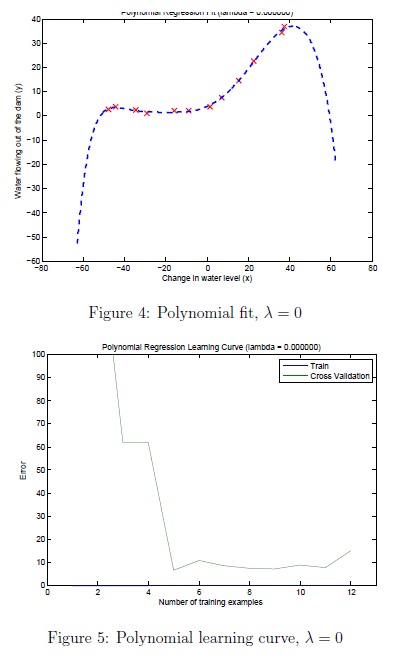

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

## 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

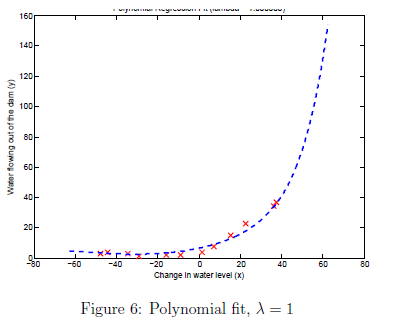

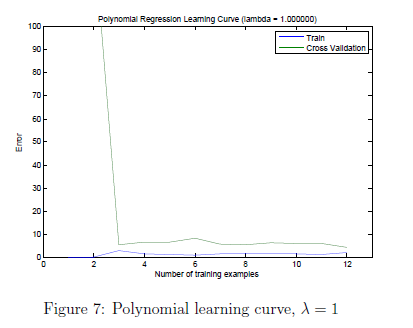

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

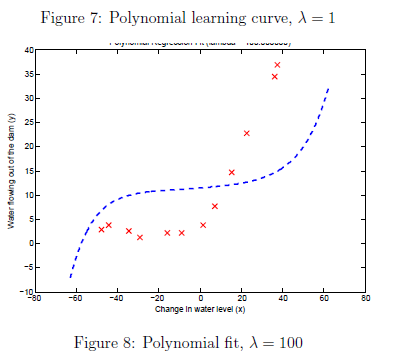

## 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');
for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

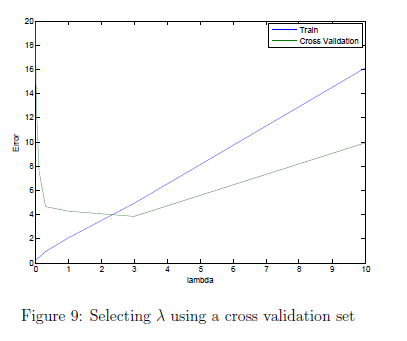

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



## 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

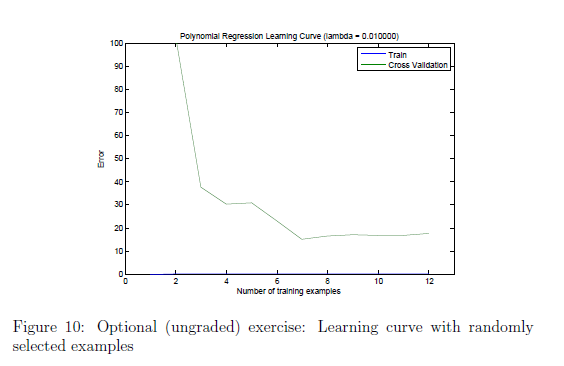

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

# Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

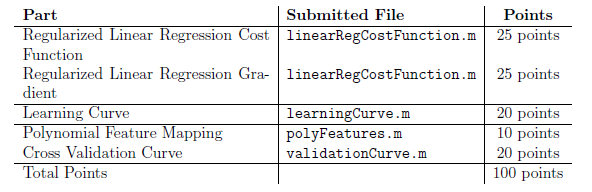

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

**Define the cleanPath function used in the environment setup section:**

Do not modify the code below.

function [] = cleanPath() 
    % cleanPath() obtains the MATLAB search path and removes any other Machine Learning exercise folders. 
    % cleanPath() also prints out the current working directory and the files contained within for reference. 
    pth = strsplit(path,pathsep); % Obtain the search path 
    pth = ([pth{contains(pth,'machine-learning-ex')},{''}]); % Obtain any ML exercise folders that have been added to the path
    rmpath(pth{:}); % Remove these folders from the path
    pwd
    dir
end